clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load
time_ms_eeg = [];

## 1.1 Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Load excel file paths for P2 and P3 ONCE per condition
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
    end

    % --- NEW: Loop through ALL subjects for this condition ---
    for s = 1:length(names_sorted)
        file_to_load = names_sorted{s}; 
        fprintf('Loading Subj %d/%d (%s) for condition: %s\n', s, length(names_sorted), file_to_load, condition);
        
        EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
        if isempty(fs), fs = EEG.srate; end
        
        if isempty(time_ms_eeg)
            time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 
        end
        
        % Extract data and store in a cell array to avoid dimension mismatch
        if ismember(condition, {'BLA', 'BLT', 'P1'})
            epoch_trials = 1:2:EEG.trials;
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials);
            
        elseif strcmp(condition, 'P2')
            epoch_trials_p2 = 1:2:EEG.trials;     
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials_p2);
            data_all_conds.P2_500{s}      = EEG.data(:, :, epoch_trials_p2_500ms);
            data_all_conds.P2_2000{s}     = EEG.data(:, :, epoch_trials_p2_2000ms);
            
        elseif strcmp(condition, 'P3')
            epoch_trials_p3 = 1:2:EEG.trials;
            data_all_conds.(condition){s}   = EEG.data(:, :, epoch_trials_p3);
            data_all_conds.P3_500{s}        = EEG.data(:, :, epoch_trials_p3_500ms);
            data_all_conds.P3_missing{s}    = EEG.data(:, :, epoch_trials_p3_missing);
        end
    end
end

Loading Subj 1/14 (binepochs filtered ICArej BLAAvgBOS10.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLAAvgBOS11.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLAAvgBOS12.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLAAvgBOS13.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLAAvgBOS15.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLAAvgBOS16.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLAAvgBOS17.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLAAvgBOS2.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLAAvgBOS3.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLAAvgBOS5.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLAAvgBOS6.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLAAvgBOS7.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLAAvgBOS8.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLAAvgBOS9.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej BLTAvgBOS10.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLTAvgBOS11.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLTAvgBOS12.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLTAvgBOS13.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLTAvgBOS15.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLTAvgBOS16.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLTAvgBOS17.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLTAvgBOS2.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLTAvgBOS3.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLTAvgBOS5.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLTAvgBOS6.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLTAvgBOS7.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLTAvgBOS8.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLTAvgBOS9.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P1AvgBOS10.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P1AvgBOS11.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P1AvgBOS12.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P1AvgBOS13.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P1AvgBOS15.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P1AvgBOS16.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P1AvgBOS17.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P1AvgBOS2.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P1AvgBOS3.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P1AvgBOS5.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P1AvgBOS6.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P1AvgBOS7.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P1AvgBOS8.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P1AvgBOS9.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P2AvgBOS10.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P2AvgBOS11.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P2AvgBOS12.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P2AvgBOS13.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P2AvgBOS15.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P2AvgBOS16.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P2AvgBOS17.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P2AvgBOS2.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P2AvgBOS3.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P2AvgBOS5.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P2AvgBOS6.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P2AvgBOS7.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P2AvgBOS8.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P2AvgBOS9.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P3AvgBOS10.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P3AvgBOS11.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P3AvgBOS12.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P3AvgBOS13.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P3AvgBOS15.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P3AvgBOS16.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P3AvgBOS17.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P3AvgBOS2.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P3AvgBOS3.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P3AvgBOS5.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P3AvgBOS6.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P3AvgBOS7.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P3AvgBOS8.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P3AvgBOS9.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1.2 Visualizing the conditions raw data

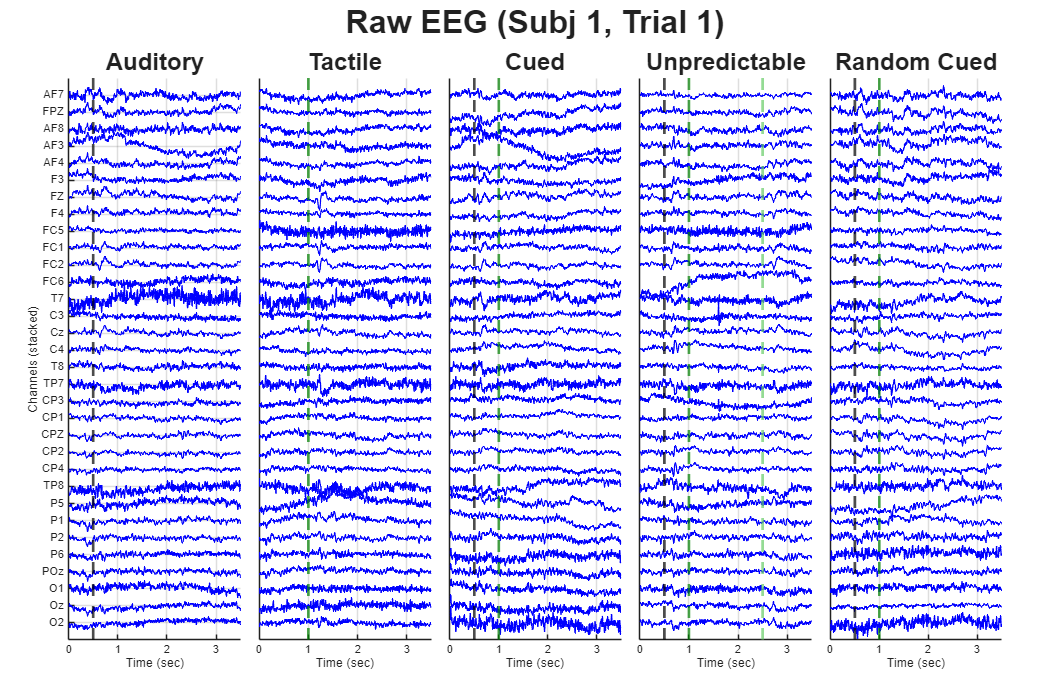

%% Visualizing Specific Trial for a Specific Subject
target_trial = 1; 
target_subject = 1; 

if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT{1}, 1))')); 
end

num_channels_plot = length(display_channels_str);
plot_conds = fieldnames(data_all_conds);
num_conds = length(conditions); % Just plotting the base conditions for now

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG (Subj %d, Trial %d)', target_subject, target_trial), 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;

for c = 1:num_conds
    cond_name = conditions{c};
    
    % Access the cell for the subject, then slice the 3rd dimension for the trial
    data_to_plot = data_all_conds.(cond_name){target_subject}(:, :, target_trial);
    
    nexttile;
    hold on
    for ch = 1:num_channels_plot
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]);
    end
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

disp('Calculating averages across trials and subjects...');

Calculating averages across trials and subjects...



cond_names = fieldnames(data_all_conds);
data_subj_avg = struct();
data_grand_avg = struct();
data_grand_std = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    num_subjects = length(data_all_conds.(c_name));
    
    % 1. Average across trials for EACH subject
    % Preallocate [Channels x Time x Subjects]
    subj_avg_matrix = zeros(num_ch, length(time_ms_eeg), num_subjects);
    
    for s = 1:num_subjects
        % Average across dim 3 (trials)
        subj_avg_matrix(:,:,s) = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
    end
    data_subj_avg.(c_name) = subj_avg_matrix;
    
    % 2. Average across subjects (Grand Average)
    data_grand_avg.(c_name) = mean(subj_avg_matrix, 3, 'omitnan');
    
    % 3. Standard Deviation across subjects (for shaded error bars)
    data_grand_std.(c_name) = std(subj_avg_matrix, 0, 3, 'omitnan');
end


% Visualizing Grand Average with STD Shading
channels_to_plot = {'AF3', 'F3', 'FZ', 'FC5', 'FC1',  'T7', 'C3', 'Cz', 'C4', 'T8', 'TP7', 'CP3', 'CP1',  'P5', 'P1', 'O1', 'Oz', 'O2'};

[~, chan_idx] = ismember(channels_to_plot, display_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
num_conds = length(conditions); 


### 2.0: Visualizing the the data averaged across subjects

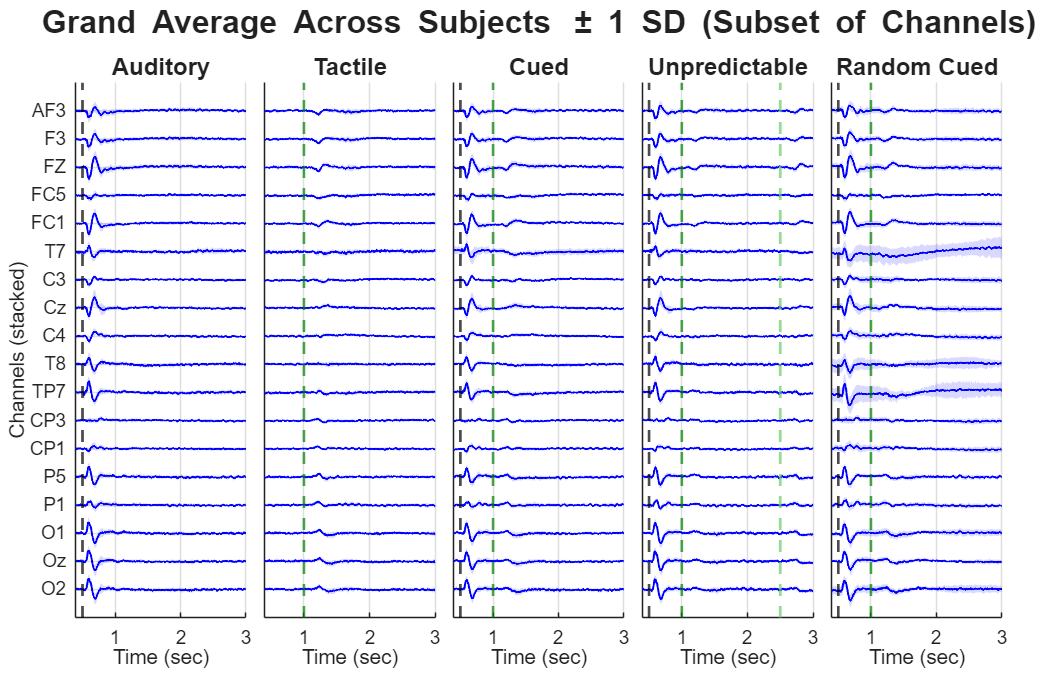

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Grand Average Across Subjects \pm 1 SD (Subset of Channels)', 'FontSize', 24, 'FontWeight', 'bold');

offset = 15; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;
time_fill = [time_ms_eeg, fliplr(time_ms_eeg)]; % X-axis for shading

for c = 1:num_conds
    cond_name = conditions{c};
    
    nexttile;
    hold on
    
    for ch = 1:num_channels_plot
        actual_ch = chan_idx(ch);
        y_shift = (num_channels_plot - ch) * offset;
        
        % Extract mean and std for this specific channel
        mu = data_grand_avg.(cond_name)(actual_ch, :) + y_shift;
        sigma = data_grand_std.(cond_name)(actual_ch, :);
        
        % Create boundaries for the shaded standard deviation
        y_bound = [mu + sigma, fliplr(mu - sigma)];
        
        % Plot Shaded STD Area first (so it sits behind the line)
        fill(time_fill, y_bound, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % Plot Mean Line
        plot(time_ms_eeg, mu, 'b', 'LineWidth', 1.5);
    end
    
    % Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); 
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

## 3.0 Prepare Data for iCAE (4D Tensor Formatting)


disp('Preparing 4D Tensors for the Convolutional Encoder...');

Preparing 4D Tensors for the Convolutional Encoder...



% Define which conditions we want to disentangle and compare
target_conds = {'BLT', 'P1'}; 
numClasses = length(target_conds);
nTime = length(time_ms_eeg);

X_list = {};
C_list = {};

for i = 1:numClasses
    cond = target_conds{i};
    
    % Concatenate all subjects' trials into one massive array for this condition
    % cat(3, ...) creates a [Channels x Time x TotalTrials] matrix
    cond_data = cat(3, data_all_conds.(cond){:}); 
    num_trials = size(cond_data, 3);
    
    % --- FORMAT X ---
    % MATLAB CNNs need [Height x Width x Channels x Batch]
    % We use permute to shift Channels to dim 3, and Time to dim 2
    % Result: [1 x Time x Channels x Trials]
    X_4D = permute(cond_data, [4, 2, 1, 3]); 
    X_list{i} = X_4D;
    
    % --- FORMAT C (One-Hot) ---
    % Result: [1 x Time x Classes x Trials]
    C_4D = zeros(1, nTime, numClasses, num_trials);
    C_4D(1, :, i, :) = 1; % Set the current class to 1 across all time points
    C_list{i} = C_4D;
end

% Combine both conditions together along the Trial dimension (Dim 4)
X_concat = cat(4, X_list{:});
C_concat = cat(4, C_list{:});

% Split into 80% Train and 20% Test
total_trials = size(X_concat, 4);
rng(42); % For reproducibility
idx_rand = randperm(total_trials);
train_idx = idx_rand(1:floor(0.8*total_trials));
test_idx = idx_rand(floor(0.8*total_trials)+1:end);

X_train_4D = X_concat(:, :, :, train_idx);
C_train_4D = C_concat(:, :, :, train_idx);
X_test_4D  = X_concat(:, :, :, test_idx);
C_test_4D  = C_concat(:, :, :, test_idx);

fprintf('Training Tensor Size: %d x %d x %d x %d\n', size(X_train_4D));

Training Tensor Size: 1 x 1792 x 32 x 1344


## 3.1 Determine Intrinsic Dimensionality (MP & MAP Tests)

function [num_factors, map_values] = velicer_map(data)
% VELICER_MAP Determines the number of factors to retain using Velicer's MAP test.
%
% Inputs:
%   data - An (n x p) matrix of raw data (n observations, p variables).
%
% Outputs:
%   num_factors - The optimal number of factors to retain.
%   map_values  - A vector containing the MAP values at each step (from 0 to p-1 factors).

    % 1. Compute the correlation matrix
    R = corrcoef(data);
    p = size(R, 1);
    
    % 2. Perform Eigenvalue Decomposition
    [eigvec, eigval_mat] = eig(R);
    eigval = diag(eigval_mat);
    
    % Sort eigenvalues and eigenvectors in descending order
    [eigval, idx] = sort(eigval, 'descend');
    eigvec = eigvec(:, idx);
    
    % Initialize array to store the MAP values
    map_values = zeros(1, p);
    
    % 3. Step 0: Calculate average squared correlation (no factors partialled out)
    R_off_diag = R - eye(p);
    map_values(1) = sum(R_off_diag(:).^2) / (p * (p - 1));
    
    % 4. Loop to partial out 1 to p-1 components
    for m = 1:(p-1)
        % Calculate the loadings for m components
        A = eigvec(:, 1:m) * diag(sqrt(eigval(1:m)));
        
        % Reproduce the correlation matrix from m components
        part_cov = R - (A * A');
        
        % Compute the partial correlation matrix
        d = diag(part_cov);
        inv_sqrt_d = diag(1 ./ sqrt(d));
        R_partial = inv_sqrt_d * part_cov * inv_sqrt_d;
        
        % Isolate off-diagonal elements
        R_partial_off = R_partial - eye(p);
        
        % Calculate the average squared partial correlation
        map_values(m+1) = sum(R_partial_off(:).^2) / (p * (p - 1));
    end
    
    % 5. Find the minimum MAP value
    % Note: MATLAB is 1-indexed, so index 1 represents 0 factors.
    [min_val, min_idx] = min(map_values);
    num_factors = min_idx - 1;
    
    % 6. Optional: Plot the results to visualize the minimum
    figure('Position',[50 50 800 500]);
    plot(0:(p-1), map_values, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
    hold on;
    plot(num_factors, map_values(min_idx), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Highlight minimum
    coordinate_text = sprintf('  Min: (%d, %.4f)', num_factors, min_val);
    text(num_factors, 0.2, coordinate_text, ...
        'VerticalAlignment', 'top', ...
        'HorizontalAlignment', 'center', ...
        'FontSize', 26, ...
        'FontWeight', 'bold', ...
        'Color', 'r');
    xlabel('Number of Factors Retained');
    ylabel('Avg. Sqrd. Partial Corr.');
    title('Velicer''s MAP Test');
    legend('MAP Values', 'Minimum (Optimal Factors)');
    set(gca,'FontSize',24);
    grid on;
    hold off;
    
    % Output the result to the console
    fprintf('Velicer''s MAP Test recommends retaining %d factors.\n', num_factors);
end

disp('Calculating Intrinsic Dimensionality...');

Calculating Intrinsic Dimensionality...



% 1. Reshape the 4D training tensor back to 2D [Channels x (Time*Trials)]
% X_train_4D is currently [1, nTime, num_ch, num_train_trials]
X_iCAE_input = permute(X_train_4D, [3, 2, 4, 1]);
X_iCAE_input = reshape(X_iCAE_input, num_ch, []);

% 2. Marchenko-Pastur Threshold
eig_vals = eig(cov(X_iCAE_input'));
[N, T] = size(X_iCAE_input);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
fprintf('Marchenko-Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko-Pastur suggests keeping 6 PCs


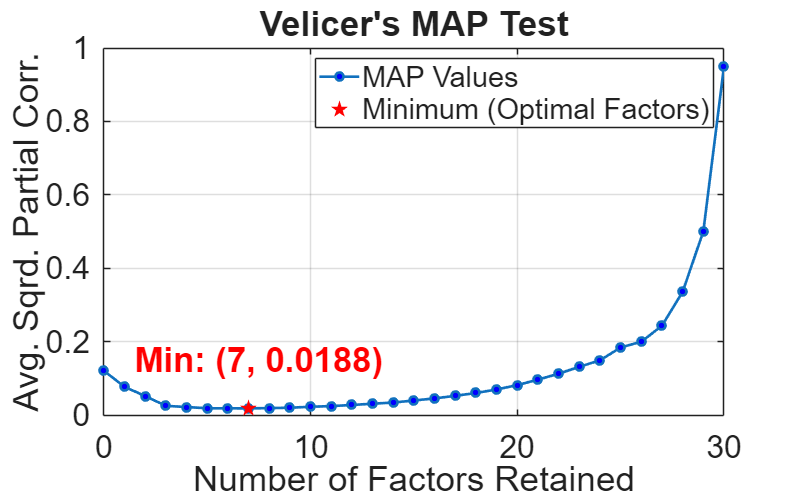

Velicer's MAP Test recommends retaining 7 factors.



% 3. Velicer's MAP Test
% (Make sure your velicer_map function is saved at the bottom of your script!)
[num_factors, map_values] = velicer_map(X_iCAE_input');

## 3.2 Configure and Train iCAE


cfg = struct();
cfg.method = "icae"; 

% --- DYNAMIC BOTTLENECK ---
% We use Velicer's MAP test result as it provides a stricter, more principled bound
cfg.bottleneckSize = num_factors; 
fprintf('Setting iCAE bottleneck size to %d based on Velicer''s MAP Test.\n', cfg.bottleneckSize);

Setting iCAE bottleneck size to 7 based on Velicer's MAP Test.



cfg.epochs = 200;
cfg.batchSize = 128;
cfg.learnRate = 1e-3;
cfg.patience = 20;
cfg.beta = 0.05;        % KL Annealing target weight
cfg.warmupEpochs = 20;  % Slowly introduce the iVAE separation

disp('Training Identifiable Convolutional Autoencoder (iCAE)...');

Training Identifiable Convolutional Autoencoder (iCAE)...


[encNet, decNet, priorNet, info] = trainEEG_iCAE(X_train_4D, C_train_4D, X_test_4D, C_test_4D, cfg);

Epoch 1/200 (Beta: 0.0000) - Train Loss: 39.3763 | Val Loss: 26.9168
Epoch 2/200 (Beta: 0.0026) - Train Loss: 24.0163 | Val Loss: 23.5263
Epoch 3/200 (Beta: 0.0053) - Train Loss: 21.0836 | Val Loss: 21.1000
Epoch 4/200 (Beta: 0.0079) - Train Loss: 19.5343 | Val Loss: 19.4246
Epoch 5/200 (Beta: 0.0105) - Train Loss: 18.3679 | Val Loss: 18.8465
Epoch 6/200 (Beta: 0.0132) - Train Loss: 17.9676 | Val Loss: 18.9516
Epoch 7/200 (Beta: 0.0158) - Train Loss: 17.7903 | Val Loss: 18.4854
Epoch 8/200 (Beta: 0.0184) - Train Loss: 17.0745 | Val Loss: 18.1914
Epoch 9/200 (Beta: 0.0211) - Train Loss: 17.1429 | Val Loss: 18.0136
Epoch 10/200 (Beta: 0.0237) - Train Loss: 16.8811 | Val Loss: 17.8329
Epoch 11/200 (Beta: 0.0263) - Train Loss: 16.6255 | Val Loss: 17.6662
Epoch 12/200 (Beta: 0.0289) - Train Loss: 16.6522 | Val Loss: 17.5621
Epoch 13/200 (Beta: 0.0316) - Train Loss: 16.5191 | Val Loss: 17.4122
Epoch 14/200 (Beta: 0.0342) - Train Loss: 16.4392 | Val Loss: 17.6954
Epoch 15/200 (Beta: 0.0368) -

## 3.3 Plot Training and Validation Loss

fprintf('Plotting training and validation loss...\n');

Plotting training and validation loss...


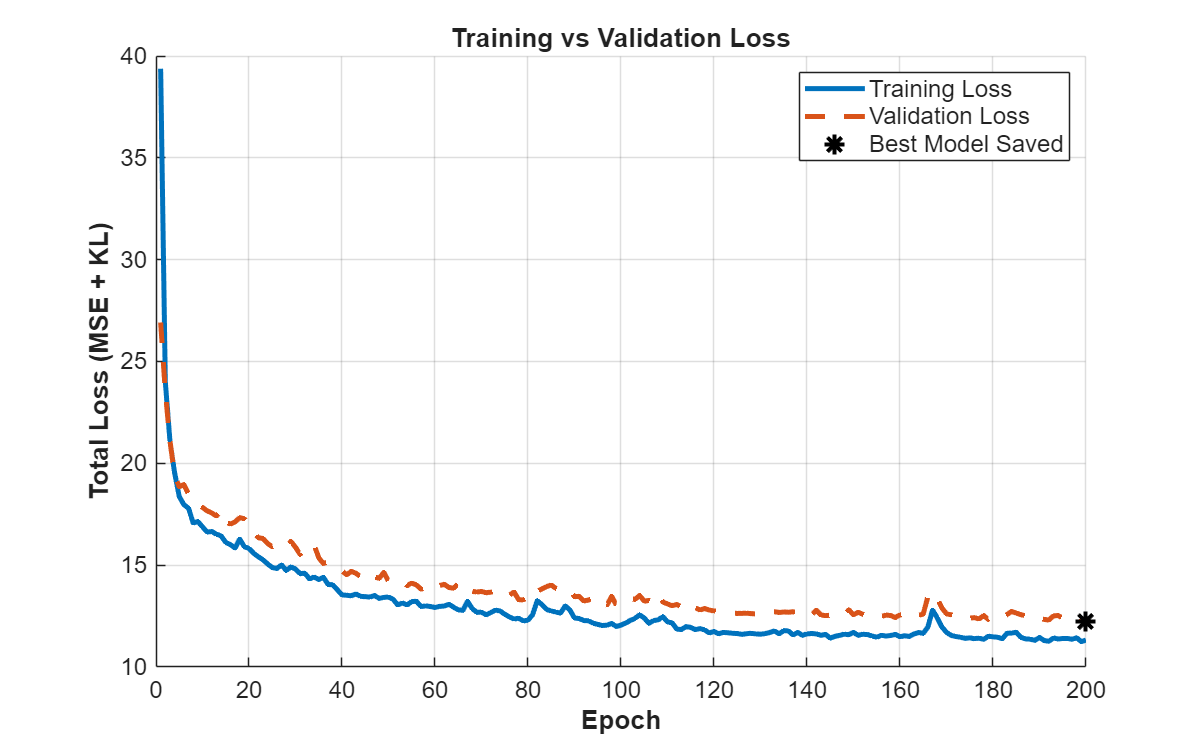

figure('Position', [150 150 800 500]);
hold on;
% Plot Train and Val loss
epochs_trained = length(info.lossHistory);
plot(1:epochs_trained, info.lossHistory, '-', 'LineWidth', 2.5, 'Color', [0 0.4470 0.7410], 'DisplayName', 'Training Loss');
plot(1:epochs_trained, info.valLossHistory, '--', 'LineWidth', 2.5, 'Color', [0.8500 0.3250 0.0980], 'DisplayName', 'Validation Loss');

% Mark the best epoch (where the weights were actually saved)
[bestLoss, bestEpoch] = min(info.valLossHistory);
plot(bestEpoch, bestLoss, 'k*', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Best Model Saved');
hold off;

grid on;
legend('Location', 'northeast', 'FontSize', 12);
xlabel('Epoch', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Total Loss (MSE + KL)', 'FontSize', 14, 'FontWeight', 'bold');
title('Training vs Validation Loss', 'FontSize', 16);
set(gca, 'FontSize', 12);

## 4.0 Extract and Plot Latent Trajectories (dPCA Equivalent)


disp('Extracting Latent Trajectories for Grand Averages...');

Extracting Latent Trajectories for Grand Averages...


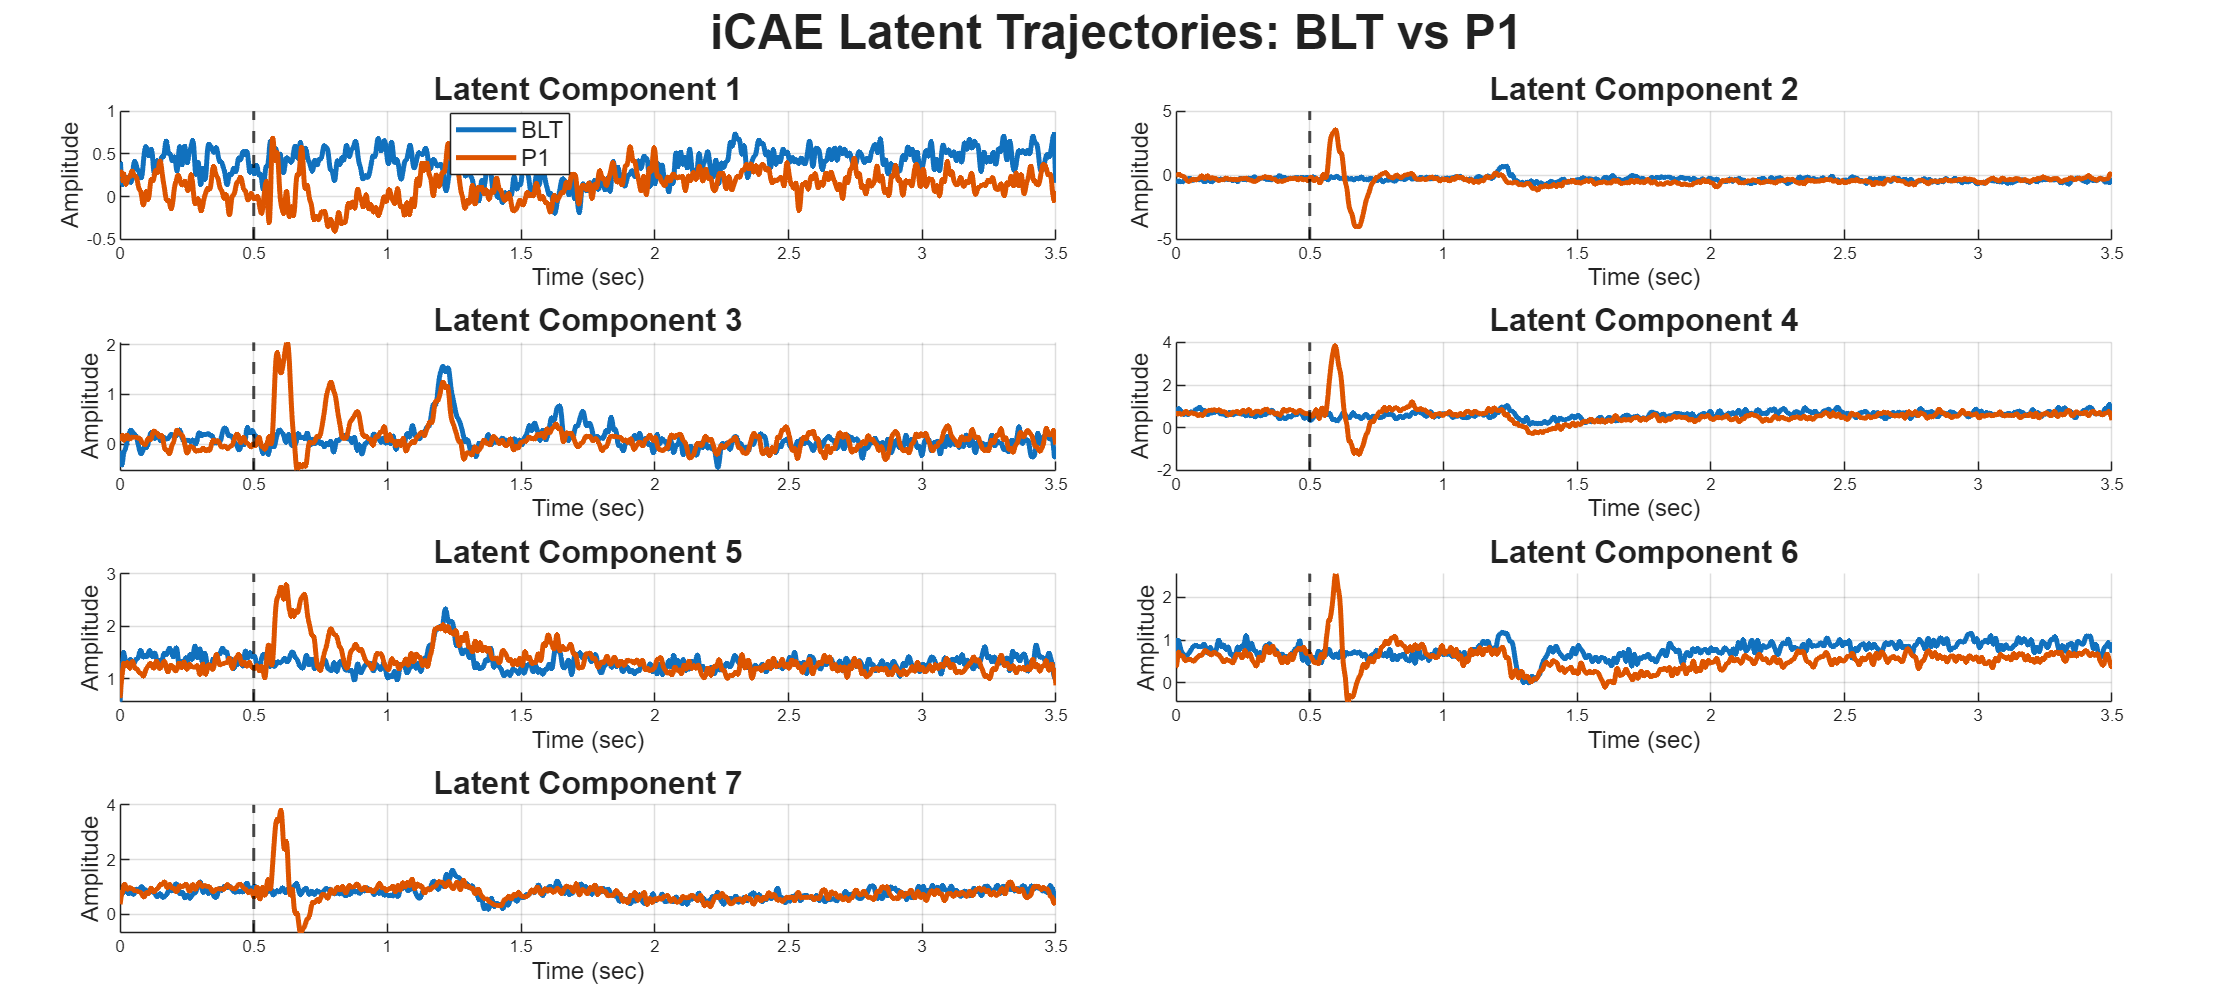


Z_trajectories = struct();
colors = lines(numClasses);

figure('Position', [100, 100, 1800, 800]);
t = tiledlayout(ceil(cfg.bottleneckSize/2),2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'iCAE Latent Trajectories: BLT vs P1', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:numClasses
    cond = target_conds{i};
    
    % 1. Get the 2D Grand Average [Channels x Time]
    avg_data = data_grand_avg.(cond); 
    
    % 2. Reshape to 4D for the network: [1 x Time x Channels x 1]
    X_avg_4D = reshape(avg_data.', 1, nTime, num_ch, 1);
    
    % 3. Create the condition label for the average
    C_avg_4D = zeros(1, nTime, numClasses, 1);
    C_avg_4D(1, :, i, 1) = 1;
    
    % 4. Pass through the trained Encoder
    XC_dl = cat(3, dlarray(X_avg_4D, 'SSCB'), dlarray(C_avg_4D, 'SSCB'));
    [Z_mu_dl, ~] = forward(encNet, XC_dl);
    
    % 5. Extract data: squeeze removes the 1-dimensions, leaving [Time x BottleneckSize]
    Z_traj = squeeze(extractdata(Z_mu_dl)); 
    Z_trajectories.(cond) = Z_traj;
end

% --- Plot 1D Trajectories over Time ---
for b = 1:cfg.bottleneckSize
    nexttile; hold on;
    for i = 1:numClasses
        cond = target_conds{i};
        % Plot the time-series for Latent Dimension 'b'
        plot(time_ms_eeg, Z_trajectories.(cond)(:, b), 'Color', colors(i,:), 'LineWidth', 2.5, 'DisplayName', cond);
    end
    
    % Add event markers for visual reference
    xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility','off'); % Stimulus onset
    
    title(sprintf('Latent Component %d', b), 'FontSize', 16);
    xlabel('Time (sec)', 'FontSize', 12); 
    ylabel('Amplitude', 'FontSize', 12);
    grid on;
    
    if b == 1
        legend('Location', 'best', 'FontSize', 12);
    end
    hold off;
end

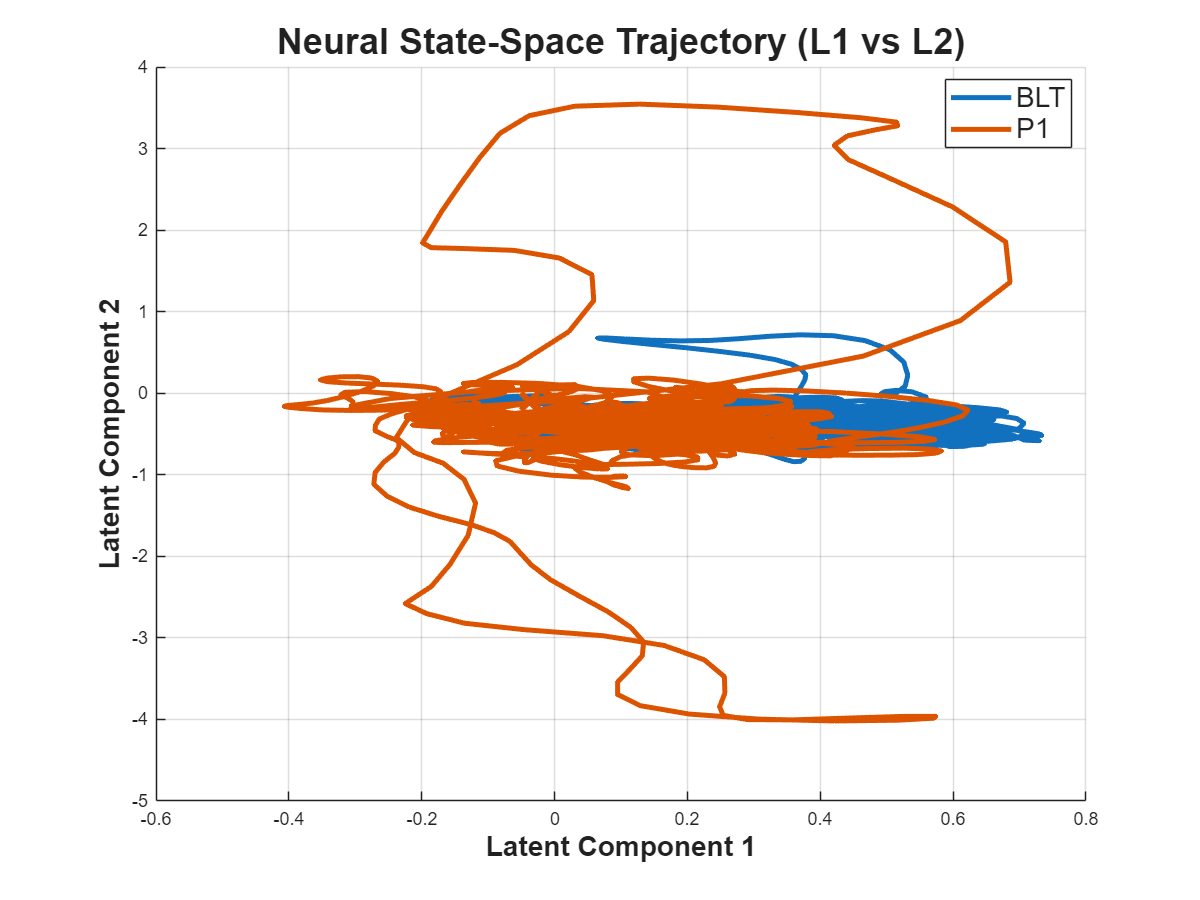


%% 4.1 State-Space Trajectory Analysis (Latent 1 vs Latent 2)
% This creates the classic "orbit" plot often seen in dPCA/neural manifold papers
figure('Position', [150, 150, 800, 600]);
hold on;

for i = 1:numClasses
    cond = target_conds{i};
    Z_traj = Z_trajectories.(cond);
    
    % Plot Latent 1 on X-axis, Latent 2 on Y-axis
    plot(Z_traj(:, 1), Z_traj(:, 2), 'Color', colors(i,:), 'LineWidth', 2.5, 'DisplayName', cond);
    
    % Mark the Start (Circle) and End (X) of the trial
    scatter(Z_traj(1, 1), Z_traj(1, 2), 120, colors(i,:), 'filled', 'o', 'HandleVisibility', 'off'); 
    scatter(Z_traj(end, 1), Z_traj(end, 2), 150, colors(i,:), 'x', 'LineWidth', 3, 'HandleVisibility', 'off'); 
end

xlabel('Latent Component 1', 'FontSize', 14, 'FontWeight', 'bold'); 
ylabel('Latent Component 2', 'FontSize', 14, 'FontWeight', 'bold');
title('Neural State-Space Trajectory (L1 vs L2)', 'FontSize', 18);
legend('Location', 'best', 'FontSize', 14);
grid on; hold off;

## 5.0 Define Condition Groups and Prepare Loop to run all condtion pairs (of two)

%% 3.0 Define Condition Groups and Prepare Loop
disp('Initializing iCAE Pairwise Loop...');

Initializing iCAE Pairwise Loop...


Running iCAE for Group: MS | Pair: Auditory vs Cued


Training Tensor Size: 1 x 1792 x 32 x 1344


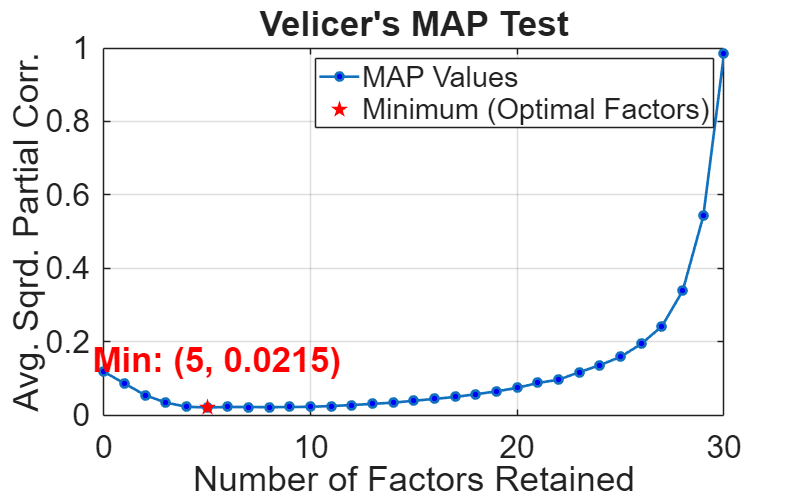

Velicer's MAP Test recommends retaining 5 factors.


Setting iCAE bottleneck size to 5 based on Velicer's MAP Test.


Training Identifiable Convolutional Autoencoder (iCAE)...


Epoch 1/200 (Beta: 0.0000) - Train Loss: 65.8881 | Val Loss: 63.5508
Epoch 2/200 (Beta: 0.0026) - Train Loss: 55.4111 | Val Loss: 53.2004
Epoch 3/200 (Beta: 0.0053) - Train Loss: 46.8257 | Val Loss: 47.0947
Epoch 4/200 (Beta: 0.0079) - Train Loss: 42.6090 | Val Loss: 44.8372
Epoch 5/200 (Beta: 0.0105) - Train Loss: 41.2098 | Val Loss: 43.5884
Epoch 6/200 (Beta: 0.0132) - Train Loss: 39.9744 | Val Loss: 42.8504
Epoch 7/200 (Beta: 0.0158) - Train Loss: 39.7259 | Val Loss: 42.3896
Epoch 8/200 (Beta: 0.0184) - Train Loss: 39.0676 | Val Loss: 42.0100
Epoch 9/200 (Beta: 0.0211) - Train Loss: 39.0497 | Val Loss: 41.7532
Epoch 10/200 (Beta: 0.0237) - Train Loss: 38.2892 | Val Loss: 41.4509
Epoch 11/200 (Beta: 0.0263) - Train Loss: 37.7653 | Val Loss: 41.2271
Epoch 12/200 (Beta: 0.0289) - Train Loss: 37.2022 | Val Loss: 40.9844
Epoch 13/200 (Beta: 0.0316) - Train Loss: 38.2680 | Val Loss: 40.7200
Epoch 14/200 (Beta: 0.0342) - Train Loss: 37.3234 | Val Loss: 40.5235
Epoch 15/200 (Beta: 0.0368) -

Extracting Latent Trajectories for Grand Averages...


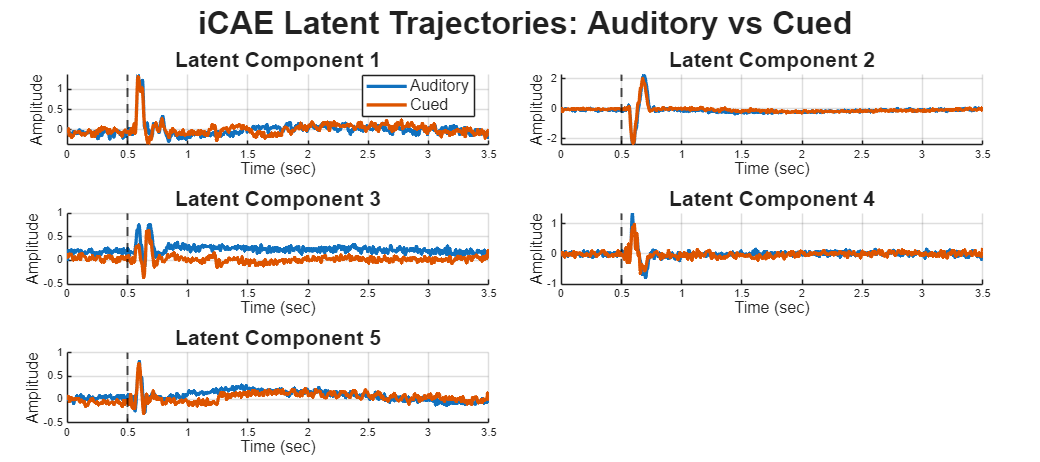

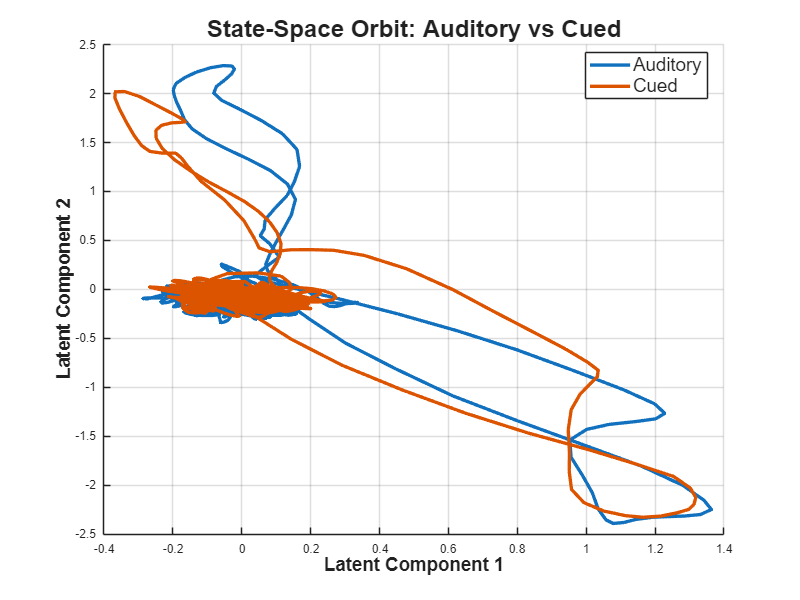

Finished Pair: Auditory vs Cued



Running iCAE for Group: MS | Pair: Tactile vs Cued


Training Tensor Size: 1 x 1792 x 32 x 1344


Velicer's MAP Test recommends retaining 7 factors.


Setting iCAE bottleneck size to 7 based on Velicer's MAP Test.


Training Identifiable Convolutional Autoencoder (iCAE)...


Epoch 1/200 (Beta: 0.0000) - Train Loss: 54.9520 | Val Loss: 54.0434
Epoch 2/200 (Beta: 0.0026) - Train Loss: 43.3366 | Val Loss: 44.5736
Epoch 3/200 (Beta: 0.0053) - Train Loss: 37.7799 | Val Loss: 39.7950
Epoch 4/200 (Beta: 0.0079) - Train Loss: 35.0446 | Val Loss: 37.5297
Epoch 5/200 (Beta: 0.0105) - Train Loss: 33.3622 | Val Loss: 35.6733
Epoch 6/200 (Beta: 0.0132) - Train Loss: 32.2401 | Val Loss: 34.1063
Epoch 7/200 (Beta: 0.0158) - Train Loss: 30.5815 | Val Loss: 33.3261
Epoch 8/200 (Beta: 0.0184) - Train Loss: 30.4151 | Val Loss: 32.7647
Epoch 9/200 (Beta: 0.0211) - Train Loss: 30.3376 | Val Loss: 32.2294
Epoch 10/200 (Beta: 0.0237) - Train Loss: 29.9768 | Val Loss: 31.8606
Epoch 11/200 (Beta: 0.0263) - Train Loss: 29.8948 | Val Loss: 31.5530
Epoch 12/200 (Beta: 0.0289) - Train Loss: 29.5760 | Val Loss: 31.3344
Epoch 13/200 (Beta: 0.0316) - Train Loss: 29.3993 | Val Loss: 31.0910
Epoch 14/200 (Beta: 0.0342) - Train Loss: 29.1798 | Val Loss: 30.9041
Epoch 15/200 (Beta: 0.0368) -

Extracting Latent Trajectories for Grand Averages...


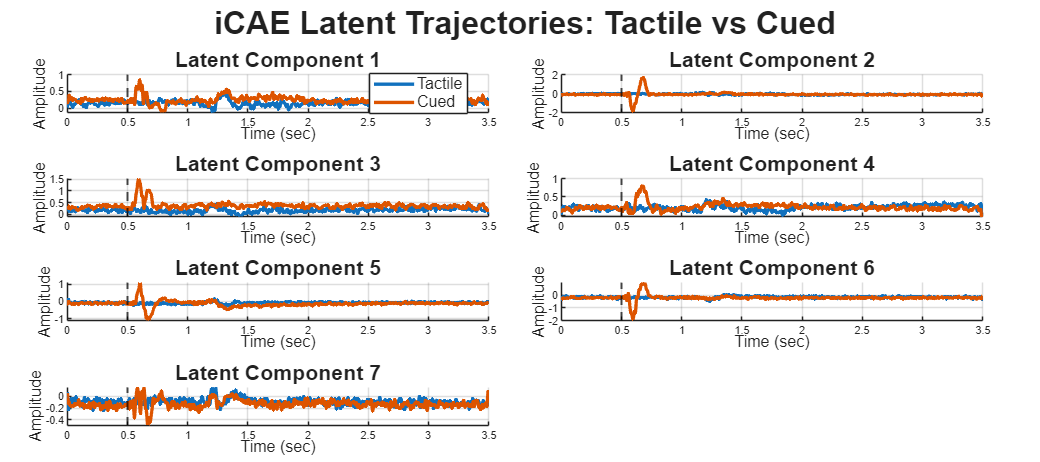

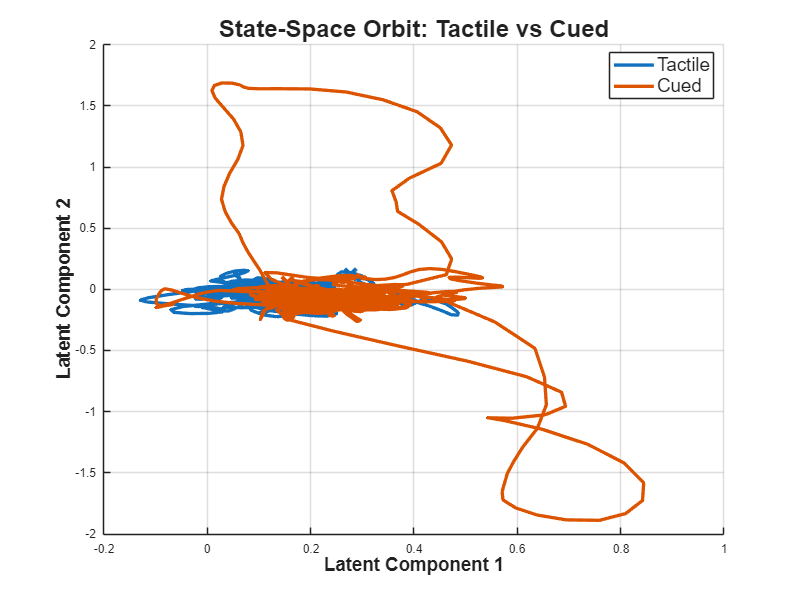

Finished Pair: Tactile vs Cued



Running iCAE for Group: Temp | Pair: Cued vs Unpred. 500


Training Tensor Size: 1 x 1792 x 32 x 1008


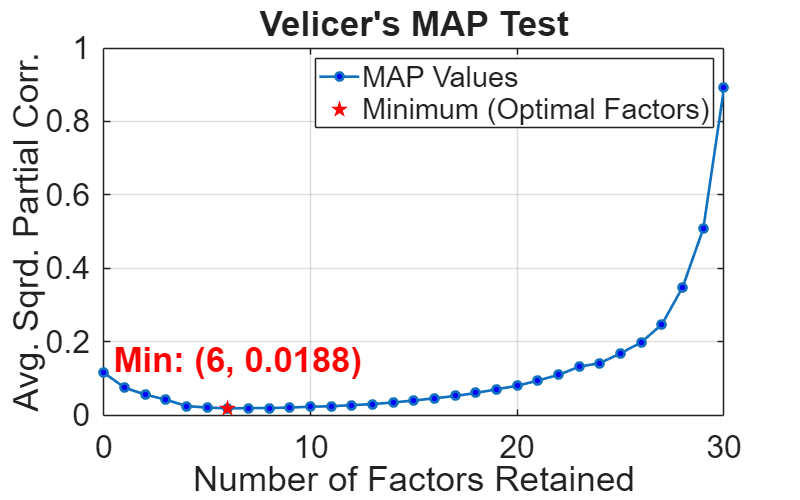

Velicer's MAP Test recommends retaining 6 factors.


Setting iCAE bottleneck size to 6 based on Velicer's MAP Test.


Training Identifiable Convolutional Autoencoder (iCAE)...


Epoch 1/200 (Beta: 0.0000) - Train Loss: 66.2580 | Val Loss: 55.9199
Epoch 2/200 (Beta: 0.0026) - Train Loss: 59.4107 | Val Loss: 50.2392
Epoch 3/200 (Beta: 0.0053) - Train Loss: 58.1613 | Val Loss: 46.2750
Epoch 4/200 (Beta: 0.0079) - Train Loss: 54.0772 | Val Loss: 44.3060
Epoch 5/200 (Beta: 0.0105) - Train Loss: 47.9082 | Val Loss: 42.5577
Epoch 6/200 (Beta: 0.0132) - Train Loss: 49.1145 | Val Loss: 41.0849
Epoch 7/200 (Beta: 0.0158) - Train Loss: 44.4168 | Val Loss: 39.7489
Epoch 8/200 (Beta: 0.0184) - Train Loss: 44.7209 | Val Loss: 38.6207
Epoch 9/200 (Beta: 0.0211) - Train Loss: 41.0532 | Val Loss: 37.7644
Epoch 10/200 (Beta: 0.0237) - Train Loss: 41.9832 | Val Loss: 37.1260
Epoch 11/200 (Beta: 0.0263) - Train Loss: 38.5747 | Val Loss: 36.6651
Epoch 12/200 (Beta: 0.0289) - Train Loss: 40.4010 | Val Loss: 36.2915
Epoch 13/200 (Beta: 0.0316) - Train Loss: 39.9662 | Val Loss: 36.0046
Epoch 14/200 (Beta: 0.0342) - Train Loss: 40.3726 | Val Loss: 35.7631
Epoch 15/200 (Beta: 0.0368) -

Extracting Latent Trajectories for Grand Averages...


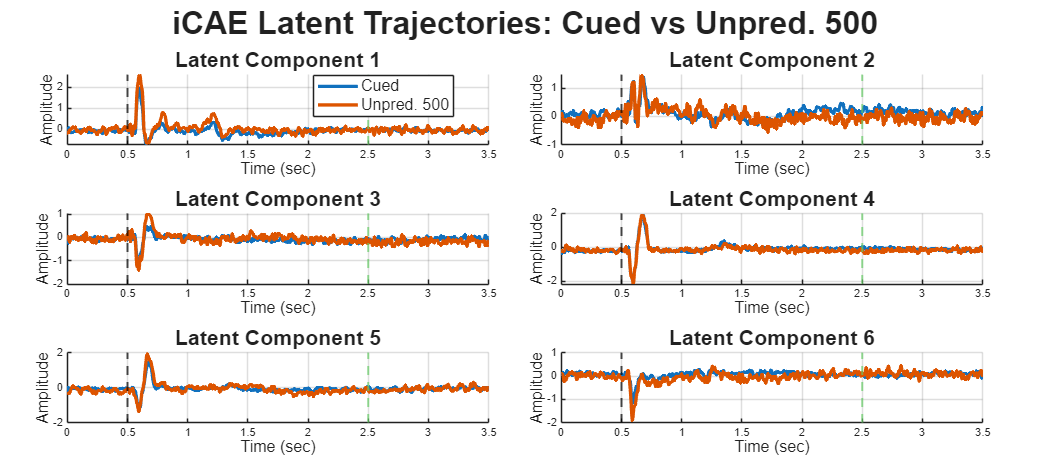

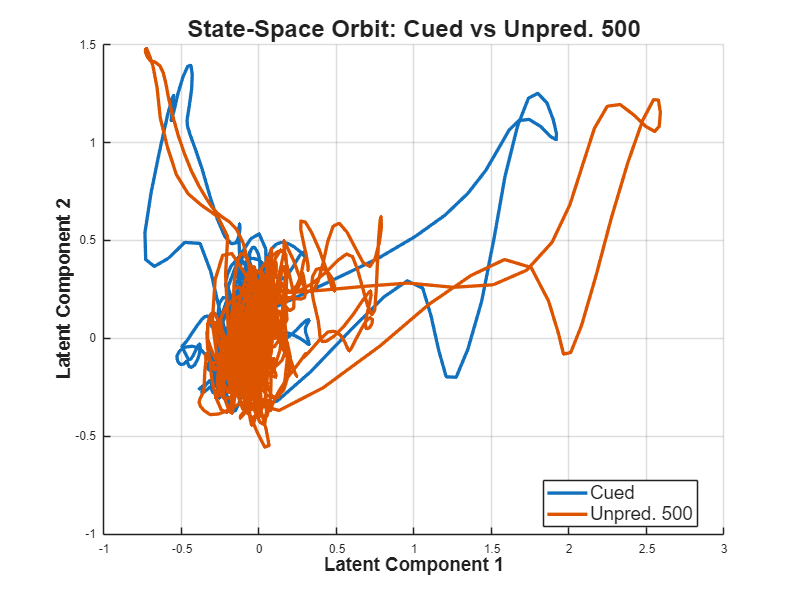

Finished Pair: Cued vs Unpred. 500



Running iCAE for Group: Temp | Pair: Cued vs Unpred. 2000


Training Tensor Size: 1 x 1792 x 32 x 1008


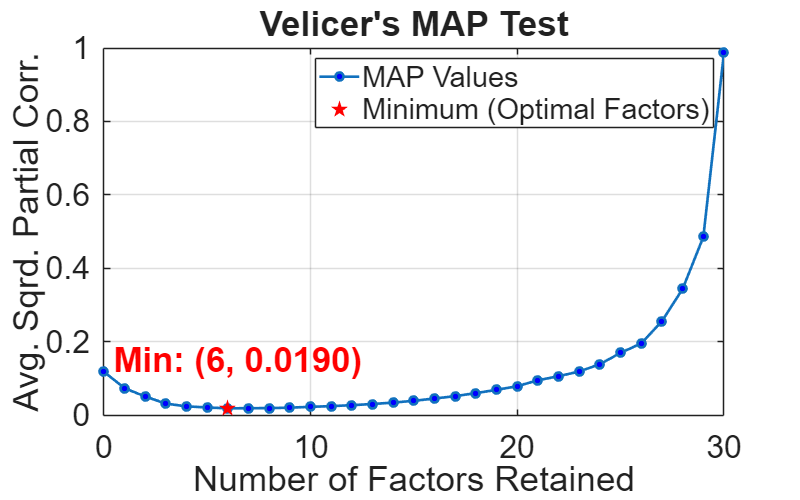

Velicer's MAP Test recommends retaining 6 factors.


Setting iCAE bottleneck size to 6 based on Velicer's MAP Test.


Training Identifiable Convolutional Autoencoder (iCAE)...


Epoch 1/200 (Beta: 0.0000) - Train Loss: 61.3538 | Val Loss: 54.9731
Epoch 2/200 (Beta: 0.0026) - Train Loss: 57.1995 | Val Loss: 49.3603
Epoch 3/200 (Beta: 0.0053) - Train Loss: 54.7889 | Val Loss: 45.5007
Epoch 4/200 (Beta: 0.0079) - Train Loss: 51.2446 | Val Loss: 43.6502
Epoch 5/200 (Beta: 0.0105) - Train Loss: 45.8617 | Val Loss: 41.9801
Epoch 6/200 (Beta: 0.0132) - Train Loss: 47.2822 | Val Loss: 40.6159
Epoch 7/200 (Beta: 0.0158) - Train Loss: 42.7156 | Val Loss: 39.3406
Epoch 8/200 (Beta: 0.0184) - Train Loss: 43.5949 | Val Loss: 38.2255
Epoch 9/200 (Beta: 0.0211) - Train Loss: 41.7202 | Val Loss: 37.3545
Epoch 10/200 (Beta: 0.0237) - Train Loss: 41.2510 | Val Loss: 36.7424
Epoch 11/200 (Beta: 0.0263) - Train Loss: 37.0401 | Val Loss: 36.2871
Epoch 12/200 (Beta: 0.0289) - Train Loss: 39.0291 | Val Loss: 35.8934
Epoch 13/200 (Beta: 0.0316) - Train Loss: 38.3787 | Val Loss: 35.5895
Epoch 14/200 (Beta: 0.0342) - Train Loss: 38.4147 | Val Loss: 35.3264
Epoch 15/200 (Beta: 0.0368) -

Extracting Latent Trajectories for Grand Averages...


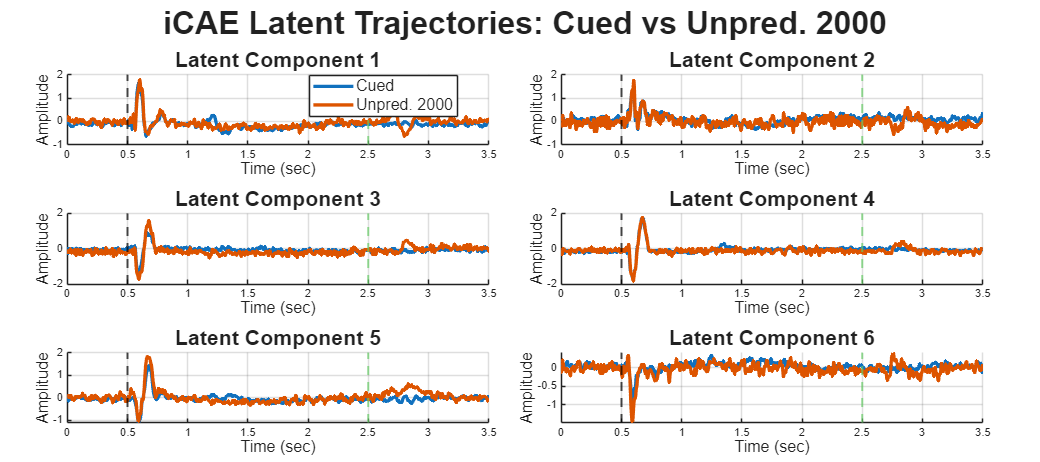

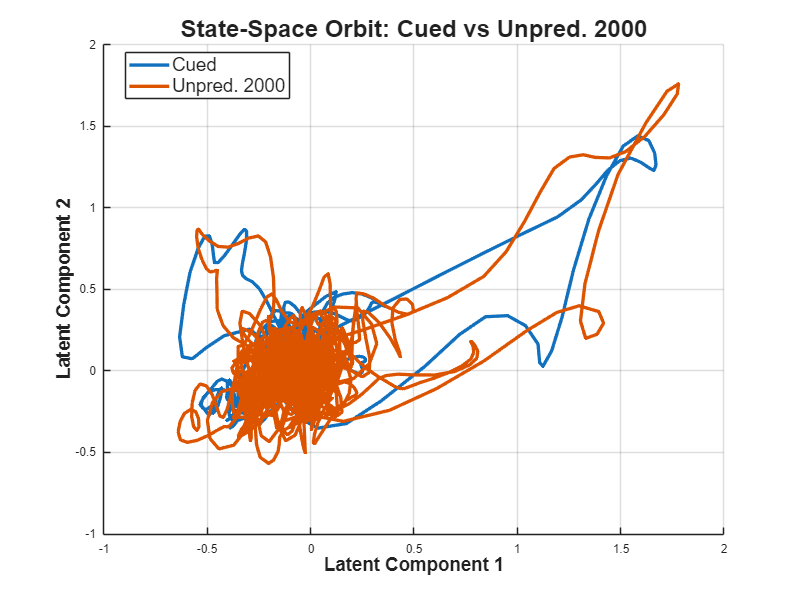

Finished Pair: Cued vs Unpred. 2000



Running iCAE for Group: Stim | Pair: Cued vs Rand. Cued 500


Training Tensor Size: 1 x 1792 x 32 x 1008


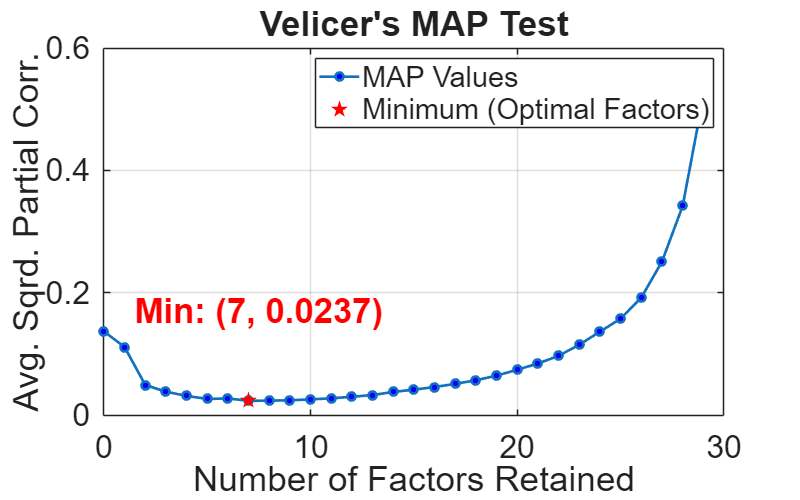

Velicer's MAP Test recommends retaining 7 factors.


Setting iCAE bottleneck size to 7 based on Velicer's MAP Test.


Training Identifiable Convolutional Autoencoder (iCAE)...


Epoch 1/200 (Beta: 0.0000) - Train Loss: 108.3786 | Val Loss: 63.8509
Epoch 2/200 (Beta: 0.0026) - Train Loss: 96.6025 | Val Loss: 58.9175
Epoch 3/200 (Beta: 0.0053) - Train Loss: 84.5998 | Val Loss: 53.6317
Epoch 4/200 (Beta: 0.0079) - Train Loss: 73.5323 | Val Loss: 50.0128
Epoch 5/200 (Beta: 0.0105) - Train Loss: 67.9629 | Val Loss: 47.6690
Epoch 6/200 (Beta: 0.0132) - Train Loss: 68.3308 | Val Loss: 46.3599
Epoch 7/200 (Beta: 0.0158) - Train Loss: 63.7999 | Val Loss: 45.5387
Epoch 8/200 (Beta: 0.0184) - Train Loss: 63.0482 | Val Loss: 44.9028
Epoch 9/200 (Beta: 0.0211) - Train Loss: 61.4266 | Val Loss: 44.4728
Epoch 10/200 (Beta: 0.0237) - Train Loss: 60.2133 | Val Loss: 44.1274
Epoch 11/200 (Beta: 0.0263) - Train Loss: 61.9147 | Val Loss: 43.8061
Epoch 12/200 (Beta: 0.0289) - Train Loss: 62.1276 | Val Loss: 43.5177
Epoch 13/200 (Beta: 0.0316) - Train Loss: 61.6087 | Val Loss: 43.2428
Epoch 14/200 (Beta: 0.0342) - Train Loss: 59.8747 | Val Loss: 42.9507
Epoch 15/200 (Beta: 0.0368) 

Extracting Latent Trajectories for Grand Averages...


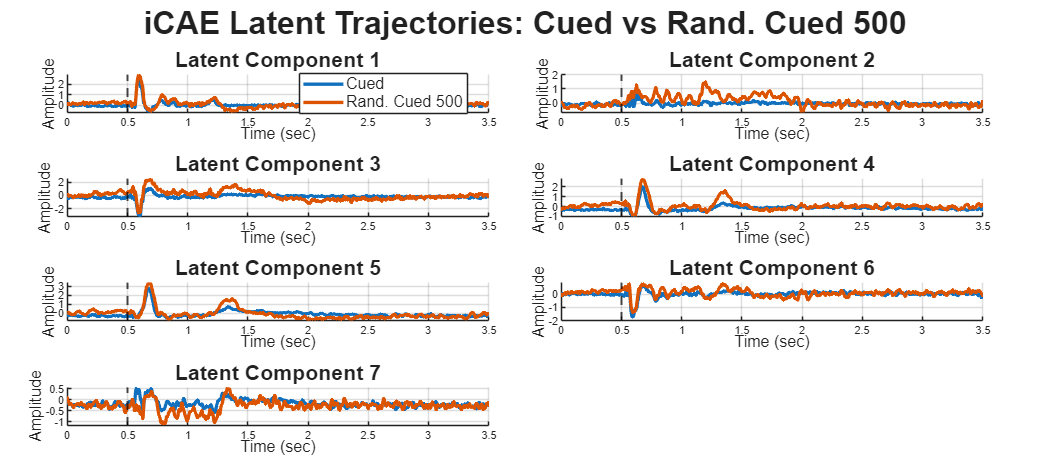

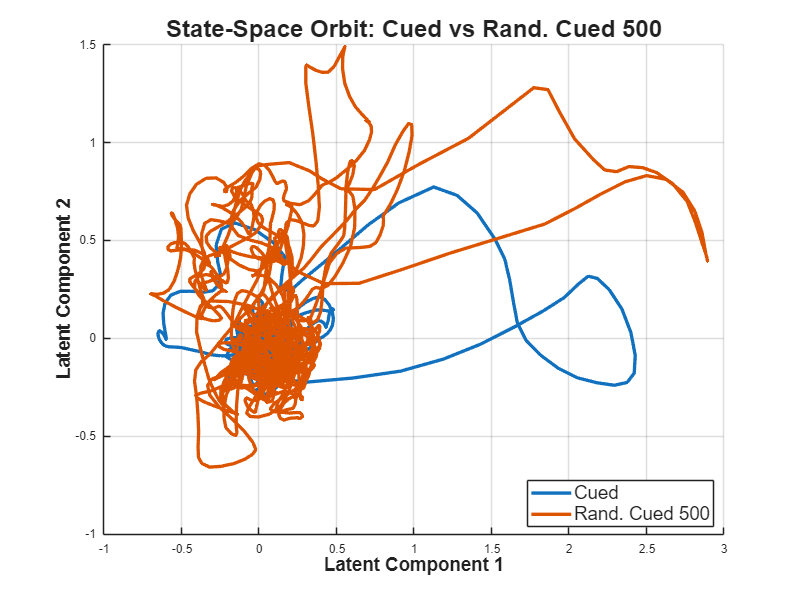

Finished Pair: Cued vs Rand. Cued 500



Running iCAE for Group: Stim | Pair: Cued vs Rand. Cued Missing


Training Tensor Size: 1 x 1792 x 32 x 1008


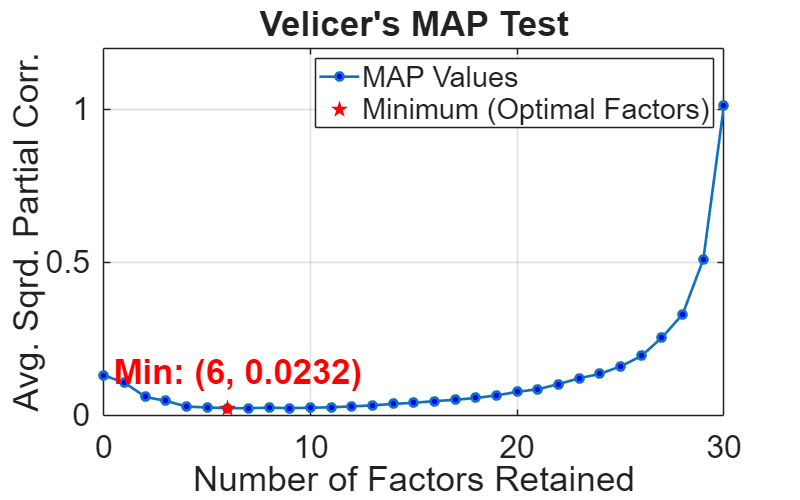

Velicer's MAP Test recommends retaining 6 factors.


Setting iCAE bottleneck size to 6 based on Velicer's MAP Test.


Training Identifiable Convolutional Autoencoder (iCAE)...


Epoch 1/200 (Beta: 0.0000) - Train Loss: 105.0046 | Val Loss: 59.5884
Epoch 2/200 (Beta: 0.0026) - Train Loss: 112.4275 | Val Loss: 55.5958
Epoch 3/200 (Beta: 0.0053) - Train Loss: 98.7024 | Val Loss: 51.0070
Epoch 4/200 (Beta: 0.0079) - Train Loss: 89.6854 | Val Loss: 47.8952
Epoch 5/200 (Beta: 0.0105) - Train Loss: 80.9619 | Val Loss: 46.1965
Epoch 6/200 (Beta: 0.0132) - Train Loss: 70.8362 | Val Loss: 45.1163
Epoch 7/200 (Beta: 0.0158) - Train Loss: 71.8825 | Val Loss: 44.2677
Epoch 8/200 (Beta: 0.0184) - Train Loss: 67.1803 | Val Loss: 43.6812
Epoch 9/200 (Beta: 0.0211) - Train Loss: 69.5201 | Val Loss: 43.2831
Epoch 10/200 (Beta: 0.0237) - Train Loss: 68.4734 | Val Loss: 42.9548
Epoch 11/200 (Beta: 0.0263) - Train Loss: 62.1810 | Val Loss: 42.7060
Epoch 12/200 (Beta: 0.0289) - Train Loss: 65.1633 | Val Loss: 42.4552
Epoch 13/200 (Beta: 0.0316) - Train Loss: 63.6858 | Val Loss: 42.2595
Epoch 14/200 (Beta: 0.0342) - Train Loss: 65.3467 | Val Loss: 42.0619
Epoch 15/200 (Beta: 0.0368)

Extracting Latent Trajectories for Grand Averages...


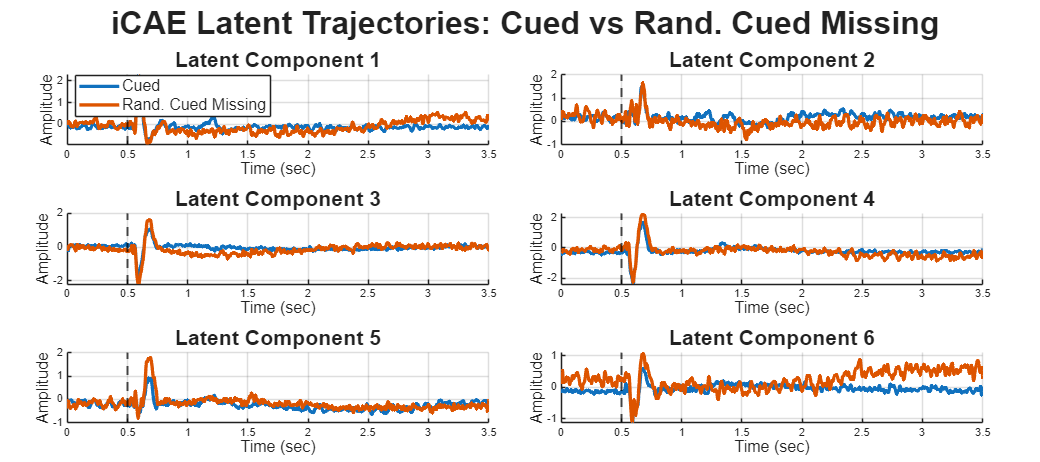

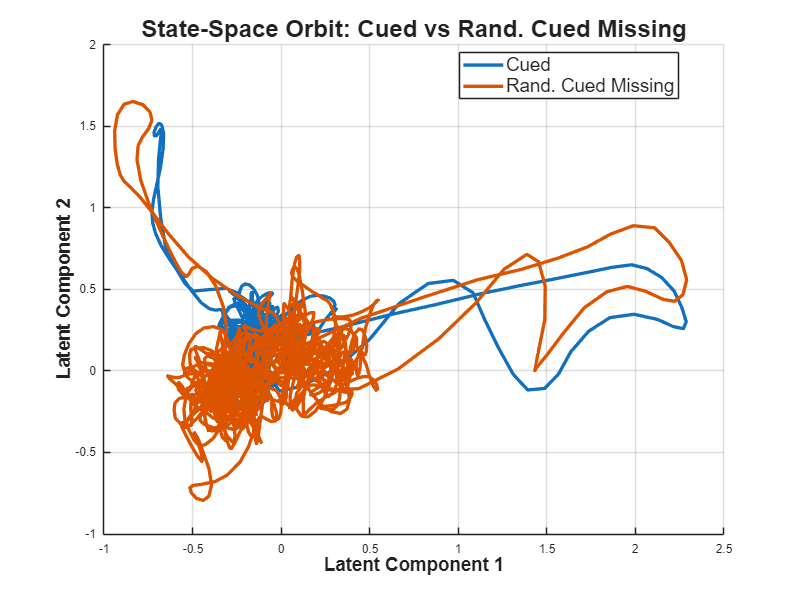

Finished Pair: Cued vs Rand. Cued Missing



nTime = length(time_ms_eeg);

% Define the groups and their specific condition pairs
compare_groups = struct();
compare_groups.MS   = {{'BLA', 'P1'}, {'BLT', 'P1'}};
compare_groups.Temp = {{'P1', 'P2_500'}, {'P1', 'P2_2000'}};
compare_groups.Stim = {{'P1', 'P3_500'}, {'P1', 'P3_missing'}};

group_names = fieldnames(compare_groups);

% Master structure to save all trajectories and networks for later analysis
iCAE_results = struct(); 

for g = 1:length(group_names)
    group = group_names{g};
    pairs = compare_groups.(group);
    
    for p = 1:length(pairs)
        target_conds = pairs{p};
        
        % --- GENERATE USER FRIENDLY NAMES ---
        friendly_conds = cell(1, length(target_conds));
        for i = 1:length(target_conds)
            c_name = target_conds{i};
            if contains(c_name, 'BLA')
                friendly_conds{i} = 'Auditory';
            elseif contains(c_name, 'BLT')
                friendly_conds{i} = 'Tactile';
            elseif strcmp(c_name, 'P1')
                friendly_conds{i} = 'Cued';
            elseif contains(c_name, 'P2_500')
                friendly_conds{i} = 'Unpred. 500';
            elseif contains(c_name, 'P2_2000')
                friendly_conds{i} = 'Unpred. 2000';
            elseif contains(c_name, 'P3_500')
                friendly_conds{i} = 'Rand. Cued 500';
            elseif contains(c_name, 'P3_missing')
                friendly_conds{i} = 'Rand. Cued Missing';
            else
                friendly_conds{i} = c_name; % Fallback
            end
        end
        
        % pair_name is used for MATLAB struct fields (no spaces allowed)
        pair_name = strjoin(target_conds, '_vs_');
        
        % friendly_pair_name is used for Display, Titles, and Prints
        friendly_pair_name = strjoin(friendly_conds, ' vs ');
        % ------------------------------------
        
        fprintf('\n======================================================\n');
        fprintf('Running iCAE for Group: %s | Pair: %s\n', group, friendly_pair_name);
        fprintf('======================================================\n');
        
        numClasses = length(target_conds);
        
        %% 3.1 Prepare 4D Tensors for the Current Pair
        X_list = {};
        C_list = {};

        for i = 1:numClasses
            cond = target_conds{i};
            % Concatenate all subjects' trials into [Channels x Time x TotalTrials]
            cond_data = cat(3, data_all_conds.(cond){:}); 
            num_trials = size(cond_data, 3);
            
            % FORMAT X: [1 x Time x Channels x Trials]
            X_4D = permute(cond_data, [4, 2, 1, 3]); 
            X_list{i} = X_4D;
            
            % FORMAT C (One-Hot): [1 x Time x Classes x Trials]
            C_4D = zeros(1, nTime, numClasses, num_trials);
            C_4D(1, :, i, :) = 1; 
            C_list{i} = C_4D;
        end

        % Combine both conditions
        X_concat = cat(4, X_list{:});
        C_concat = cat(4, C_list{:});

        % Split into 80% Train and 20% Test
        total_trials = size(X_concat, 4);
        rng(42); % For reproducibility
        idx_rand = randperm(total_trials);
        train_idx = idx_rand(1:floor(0.8*total_trials));
        test_idx = idx_rand(floor(0.8*total_trials)+1:end);

        X_train_4D = X_concat(:, :, :, train_idx);
        C_train_4D = C_concat(:, :, :, train_idx);
        X_test_4D  = X_concat(:, :, :, test_idx);
        C_test_4D  = C_concat(:, :, :, test_idx);

        fprintf('Training Tensor Size: %d x %d x %d x %d\n', size(X_train_4D));

        %% 3.2 Determine Intrinsic Dimensionality (MP & MAP Tests)
        % Reshape to 2D [Channels x (Time*Trials)] for PCA/Covariance math
        X_iCAE_input = permute(X_train_4D, [3, 2, 4, 1]);
        X_iCAE_input = reshape(X_iCAE_input, num_ch, []);

        % Velicer's MAP Test
        [num_factors, map_values] = velicer_map(X_iCAE_input');
        
        %% 3.3 Configure and Train iCAE
        cfg = struct();
        cfg.method = "icae"; 
        cfg.bottleneckSize = num_factors; % Dynamic bottleneck!
        fprintf('Setting iCAE bottleneck size to %d based on Velicer''s MAP Test.\n', cfg.bottleneckSize);

        cfg.epochs = 200;
        cfg.batchSize = 128;
        cfg.learnRate = 1e-4; % Kept low for stability
        cfg.patience = 20;
        cfg.beta = 0.05;        
        cfg.warmupEpochs = 20;  

        disp('Training Identifiable Convolutional Autoencoder (iCAE)...');
        [encNet, decNet, priorNet, info] = trainEEG_iCAE(X_train_4D, C_train_4D, X_test_4D, C_test_4D, cfg);
        
        % Save networks to master structure
        iCAE_results.(group).(pair_name).encNet = encNet;
        iCAE_results.(group).(pair_name).info = info;

        %% 4.0 Extract and Plot Latent Trajectories (dPCA Equivalent)
        disp('Extracting Latent Trajectories for Grand Averages...');

        Z_trajectories = struct();
        colors = lines(numClasses);

        % Create dynamic figure name using the friendly string
        fig_name_1D = sprintf('iCAE Latent Trajectories: %s', friendly_pair_name);
        figure('Name', fig_name_1D, 'Position', [0, 100, 1800, 800]);
        
        % Safely handle grid layout based on dynamic bottleneck size
        num_rows = max(1, ceil(cfg.bottleneckSize/2));
        t = tiledlayout(num_rows, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
        title(t, fig_name_1D, 'FontSize', 24, 'FontWeight', 'bold');

        for i = 1:numClasses
            cond = target_conds{i};
            
            % 1. Get the 2D Grand Average [Channels x Time]
            avg_data = data_grand_avg.(cond); 
            
            % 2. Reshape to 4D for the network: [1 x Time x Channels x 1]
            X_avg_4D = reshape(avg_data.', 1, nTime, num_ch, 1);
            
            % 3. Create the condition label for the average
            C_avg_4D = zeros(1, nTime, numClasses, 1);
            C_avg_4D(1, :, i, 1) = 1;
            
            % 4. Pass through the trained Encoder
            XC_dl = cat(3, dlarray(X_avg_4D, 'SSCB'), dlarray(C_avg_4D, 'SSCB'));
            [Z_mu_dl, ~] = forward(encNet, XC_dl);
            
            % 5. Extract data
            Z_traj = squeeze(extractdata(Z_mu_dl)); 
            
            % Ensure Z_traj is exactly 2D (Time x Bottleneck), handles k=1 edge case safely
            if size(Z_traj, 2) == nTime
                Z_traj = Z_traj';
            end
            
            Z_trajectories.(cond) = Z_traj;
        end
        
        % Save trajectories to master structure
        iCAE_results.(group).(pair_name).Z_trajectories = Z_trajectories;

        % --- Plot 1D Trajectories over Time ---
        for b = 1:cfg.bottleneckSize
            nexttile; hold on;
            for i = 1:numClasses
                cond = target_conds{i};
                plot_name = friendly_conds{i}; % Map to the friendly name for the legend!
                
                plot(time_ms_eeg, Z_trajectories.(cond)(:, b), 'Color', colors(i,:), 'LineWidth', 2.5, 'DisplayName', plot_name);
            end
            
            xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility','off'); % Stimulus onset
            if any(contains(target_conds, 'P2'))
                xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 1.5, 'HandleVisibility','off'); % Late stimulus
            end
            
            title(sprintf('Latent Component %d', b), 'FontSize', 16);
            xlabel('Time (sec)', 'FontSize', 12); 
            ylabel('Amplitude', 'FontSize', 12);
            grid on;
            
            if b == 1
                legend('Location', 'best', 'FontSize', 12);
            end
            hold off;
        end

        %% 4.1 State-Space Trajectory Analysis (Latent 1 vs Latent 2)
        if cfg.bottleneckSize >= 2
            fig_name_2D = sprintf('State-Space Orbit: %s', friendly_pair_name);
            figure('Name', fig_name_2D, 'Position', [150, 150, 800, 600]);
            hold on;

            for i = 1:numClasses
                cond = target_conds{i};
                plot_name = friendly_conds{i}; % Map to friendly name!
                Z_traj = Z_trajectories.(cond);
                
                % Plot Latent 1 on X-axis, Latent 2 on Y-axis
                plot(Z_traj(:, 1), Z_traj(:, 2), 'Color', colors(i,:), 'LineWidth', 2.5, 'DisplayName', plot_name);
                
                % Mark Start (Circle) and End (X)
                scatter(Z_traj(1, 1), Z_traj(1, 2), 120, colors(i,:), 'filled', 'o', 'HandleVisibility', 'off'); 
                scatter(Z_traj(end, 1), Z_traj(end, 2), 150, colors(i,:), 'x', 'LineWidth', 3, 'HandleVisibility', 'off'); 
            end

            xlabel('Latent Component 1', 'FontSize', 14, 'FontWeight', 'bold'); 
            ylabel('Latent Component 2', 'FontSize', 14, 'FontWeight', 'bold');
            title(fig_name_2D, 'FontSize', 18);
            legend('Location', 'best', 'FontSize', 14);
            grid on; hold off;
        end
        
        fprintf('Finished Pair: %s\n\n', friendly_pair_name);
    end
end

disp('All Pairwise Comparisons Complete!');

All Pairwise Comparisons Complete!


disp('All iCAE Pairwise Comparisons Complete!');

All iCAE Pairwise Comparisons Complete!


## 5.2 Define Condition Groups and Prepare Loop

disp('Initializing iCAE Group-wise Loop...');

Initializing iCAE Group-wise Loop...


Running 3-Class iCAE for Group: MS


Conditions included: BLA, BLT, P1


Training Tensor Size: 1 x 1792 x 32 x 2016


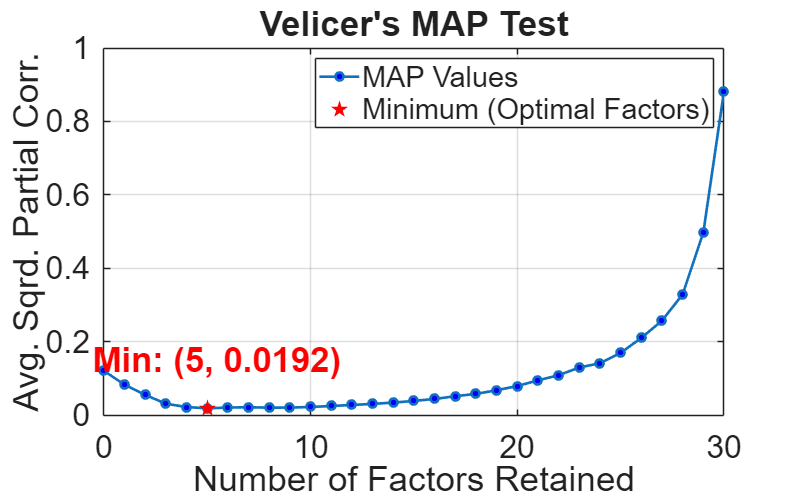

Velicer's MAP Test recommends retaining 5 factors.


Setting iCAE bottleneck size to 5 based on Velicer's MAP Test.


Training Identifiable Convolutional Autoencoder (iCAE)...


Epoch 1/200 (Beta: 0.0000) - Train Loss: 60.2435 | Val Loss: 50.3159
Epoch 2/200 (Beta: 0.0026) - Train Loss: 45.7736 | Val Loss: 38.6994
Epoch 3/200 (Beta: 0.0053) - Train Loss: 35.2232 | Val Loss: 33.4202
Epoch 4/200 (Beta: 0.0079) - Train Loss: 33.6860 | Val Loss: 31.6790
Epoch 5/200 (Beta: 0.0105) - Train Loss: 31.9794 | Val Loss: 30.9122
Epoch 6/200 (Beta: 0.0132) - Train Loss: 30.7738 | Val Loss: 30.6425
Epoch 7/200 (Beta: 0.0158) - Train Loss: 31.2127 | Val Loss: 30.4867
Epoch 8/200 (Beta: 0.0184) - Train Loss: 30.6906 | Val Loss: 30.4079
Epoch 9/200 (Beta: 0.0211) - Train Loss: 30.8710 | Val Loss: 30.3318
Epoch 10/200 (Beta: 0.0237) - Train Loss: 30.2587 | Val Loss: 30.2520
Epoch 11/200 (Beta: 0.0263) - Train Loss: 30.4705 | Val Loss: 30.1913
Epoch 12/200 (Beta: 0.0289) - Train Loss: 30.3175 | Val Loss: 30.1219
Epoch 13/200 (Beta: 0.0316) - Train Loss: 29.5217 | Val Loss: 30.0602
Epoch 14/200 (Beta: 0.0342) - Train Loss: 30.0687 | Val Loss: 29.9955
Epoch 15/200 (Beta: 0.0368) -

Extracting Latent Trajectories for Grand Averages...


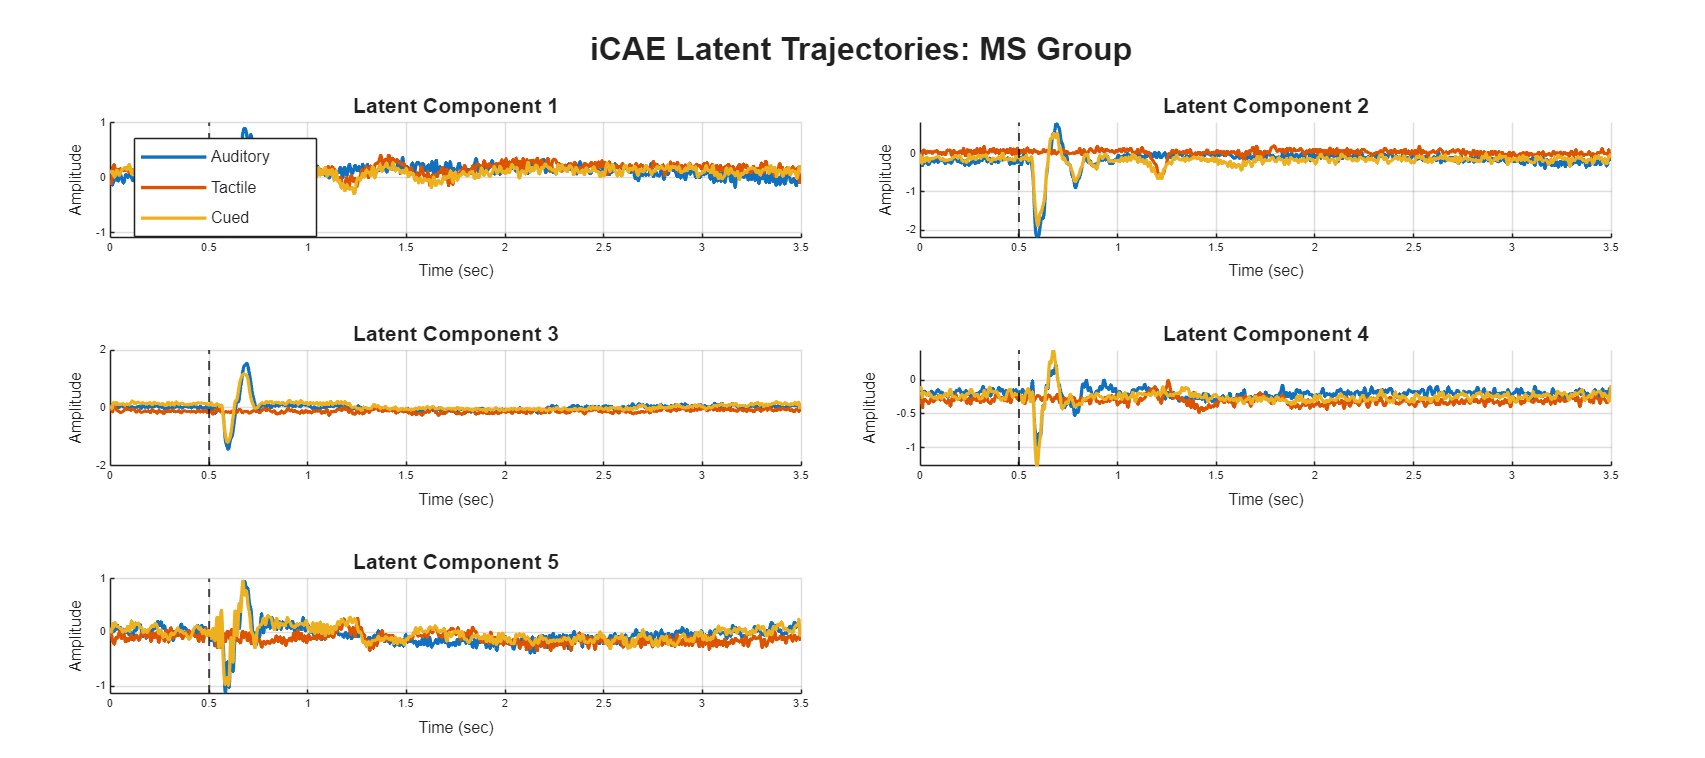

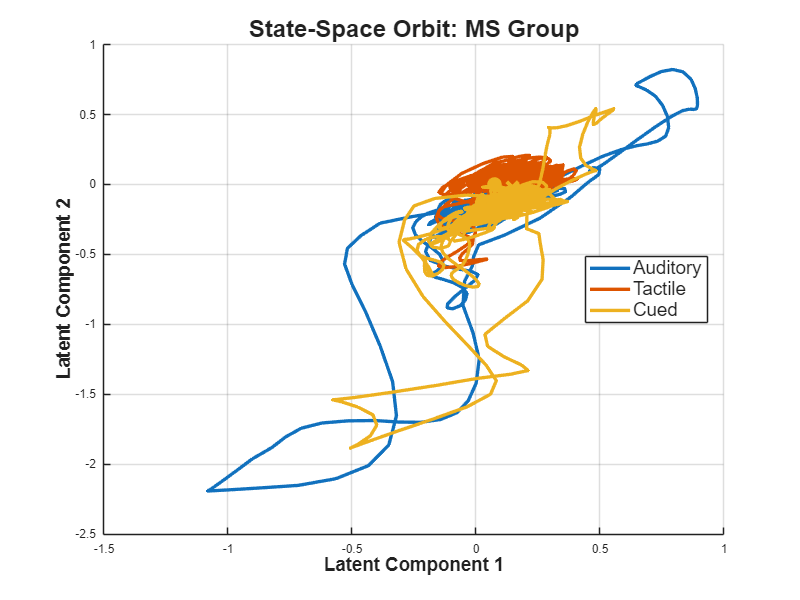

Finished Group: MS



Running 3-Class iCAE for Group: Temp


Conditions included: P1, P2_500, P2_2000


Training Tensor Size: 1 x 1792 x 32 x 1344


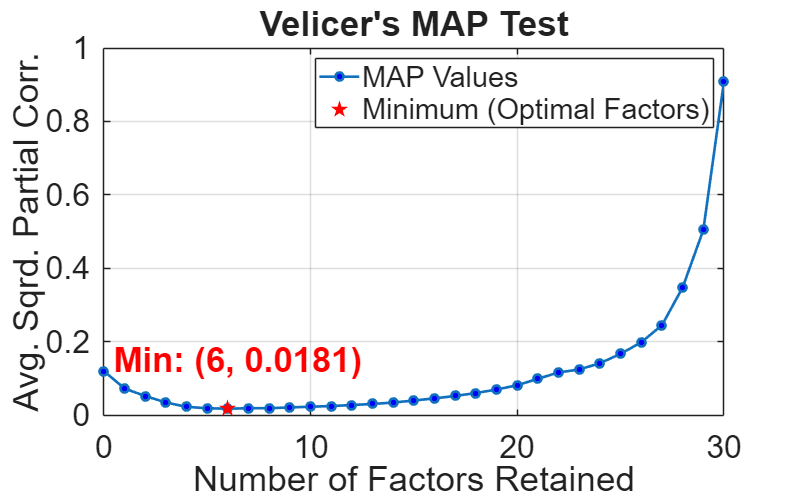

Velicer's MAP Test recommends retaining 6 factors.


Setting iCAE bottleneck size to 6 based on Velicer's MAP Test.


Training Identifiable Convolutional Autoencoder (iCAE)...


Epoch 1/200 (Beta: 0.0000) - Train Loss: 67.2233 | Val Loss: 66.2820
Epoch 2/200 (Beta: 0.0026) - Train Loss: 58.2219 | Val Loss: 59.9128
Epoch 3/200 (Beta: 0.0053) - Train Loss: 50.2469 | Val Loss: 51.8006
Epoch 4/200 (Beta: 0.0079) - Train Loss: 44.2033 | Val Loss: 47.2111
Epoch 5/200 (Beta: 0.0105) - Train Loss: 40.9605 | Val Loss: 44.4538
Epoch 6/200 (Beta: 0.0132) - Train Loss: 38.4770 | Val Loss: 42.5832
Epoch 7/200 (Beta: 0.0158) - Train Loss: 36.5950 | Val Loss: 41.5270
Epoch 8/200 (Beta: 0.0184) - Train Loss: 36.2088 | Val Loss: 40.7627
Epoch 9/200 (Beta: 0.0211) - Train Loss: 35.3216 | Val Loss: 40.1781
Epoch 10/200 (Beta: 0.0237) - Train Loss: 35.1360 | Val Loss: 39.6806
Epoch 11/200 (Beta: 0.0263) - Train Loss: 34.2098 | Val Loss: 39.3225
Epoch 12/200 (Beta: 0.0289) - Train Loss: 34.5547 | Val Loss: 39.0867
Epoch 13/200 (Beta: 0.0316) - Train Loss: 34.2948 | Val Loss: 38.8174
Epoch 14/200 (Beta: 0.0342) - Train Loss: 34.0111 | Val Loss: 38.5662
Epoch 15/200 (Beta: 0.0368) -

Extracting Latent Trajectories for Grand Averages...


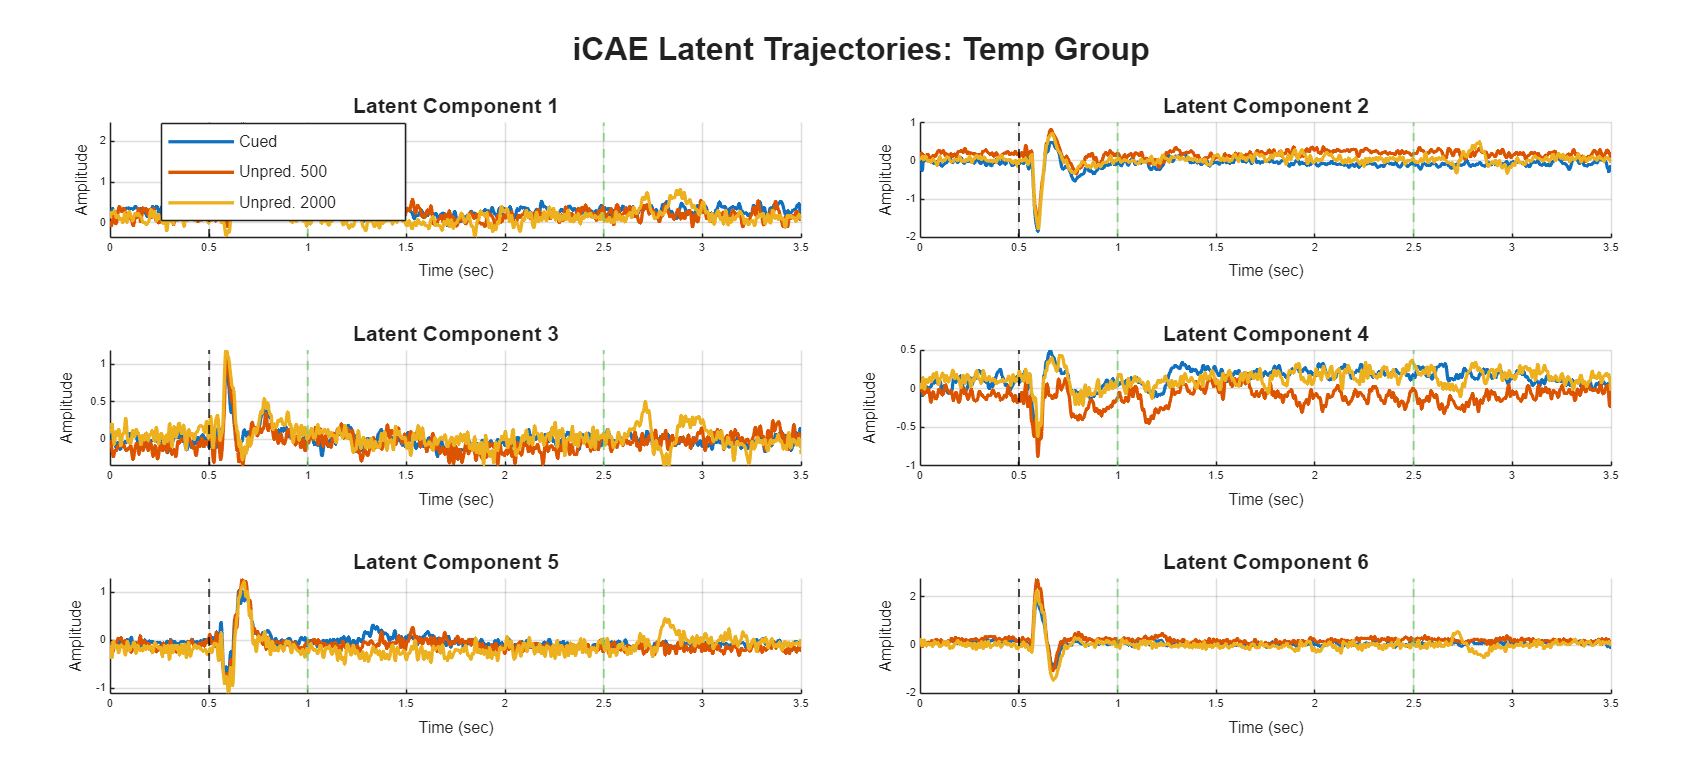

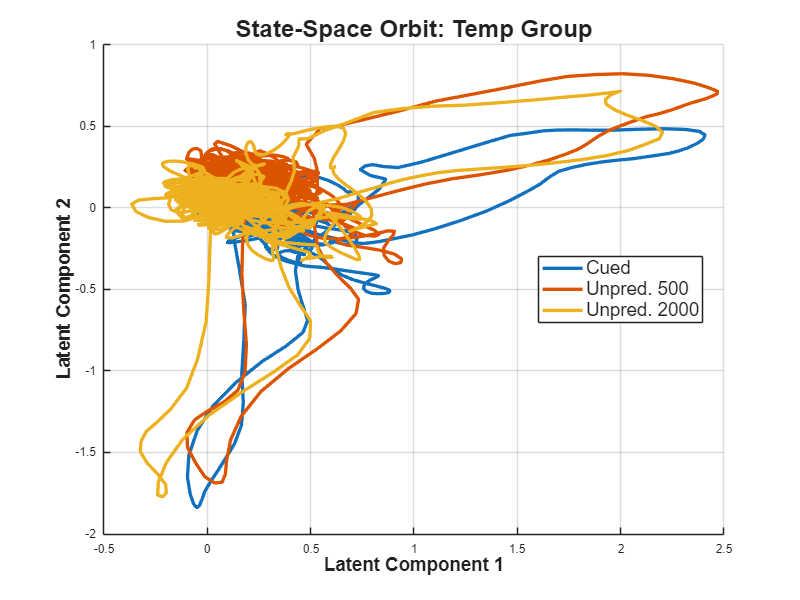

Finished Group: Temp



Running 3-Class iCAE for Group: Stim


Conditions included: P1, P3_500, P3_missing


Training Tensor Size: 1 x 1792 x 32 x 1344


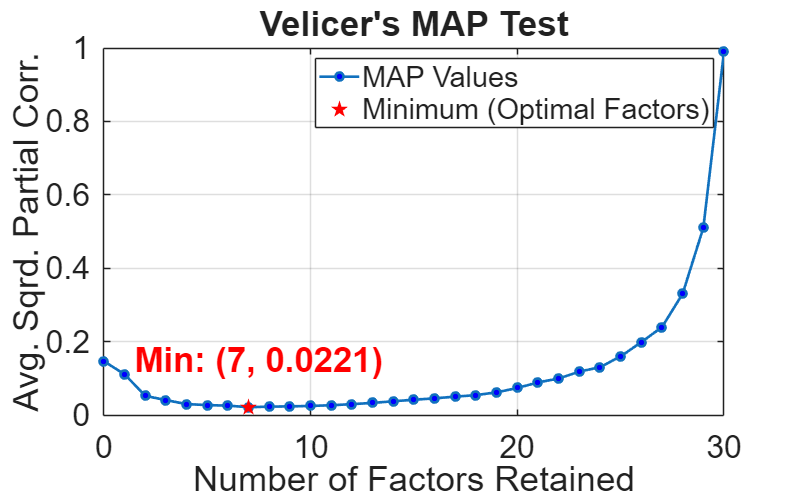

Velicer's MAP Test recommends retaining 7 factors.


Setting iCAE bottleneck size to 7 based on Velicer's MAP Test.


Training Identifiable Convolutional Autoencoder (iCAE)...


Epoch 1/200 (Beta: 0.0000) - Train Loss: 121.2898 | Val Loss: 130.3073
Epoch 2/200 (Beta: 0.0026) - Train Loss: 98.0286 | Val Loss: 109.0960
Epoch 3/200 (Beta: 0.0053) - Train Loss: 79.0076 | Val Loss: 92.0356
Epoch 4/200 (Beta: 0.0079) - Train Loss: 71.7716 | Val Loss: 83.8032
Epoch 5/200 (Beta: 0.0105) - Train Loss: 65.3347 | Val Loss: 76.6399
Epoch 6/200 (Beta: 0.0132) - Train Loss: 61.2338 | Val Loss: 71.8658
Epoch 7/200 (Beta: 0.0158) - Train Loss: 58.4618 | Val Loss: 68.8557
Epoch 8/200 (Beta: 0.0184) - Train Loss: 54.7725 | Val Loss: 67.2103
Epoch 9/200 (Beta: 0.0211) - Train Loss: 55.9134 | Val Loss: 66.5456
Epoch 10/200 (Beta: 0.0237) - Train Loss: 53.9074 | Val Loss: 66.0428
Epoch 11/200 (Beta: 0.0263) - Train Loss: 54.8585 | Val Loss: 65.6058
Epoch 12/200 (Beta: 0.0289) - Train Loss: 51.9888 | Val Loss: 65.4590
Epoch 13/200 (Beta: 0.0316) - Train Loss: 51.6602 | Val Loss: 65.3826
Epoch 14/200 (Beta: 0.0342) - Train Loss: 52.6033 | Val Loss: 65.4172
Epoch 15/200 (Beta: 0.0368

Extracting Latent Trajectories for Grand Averages...


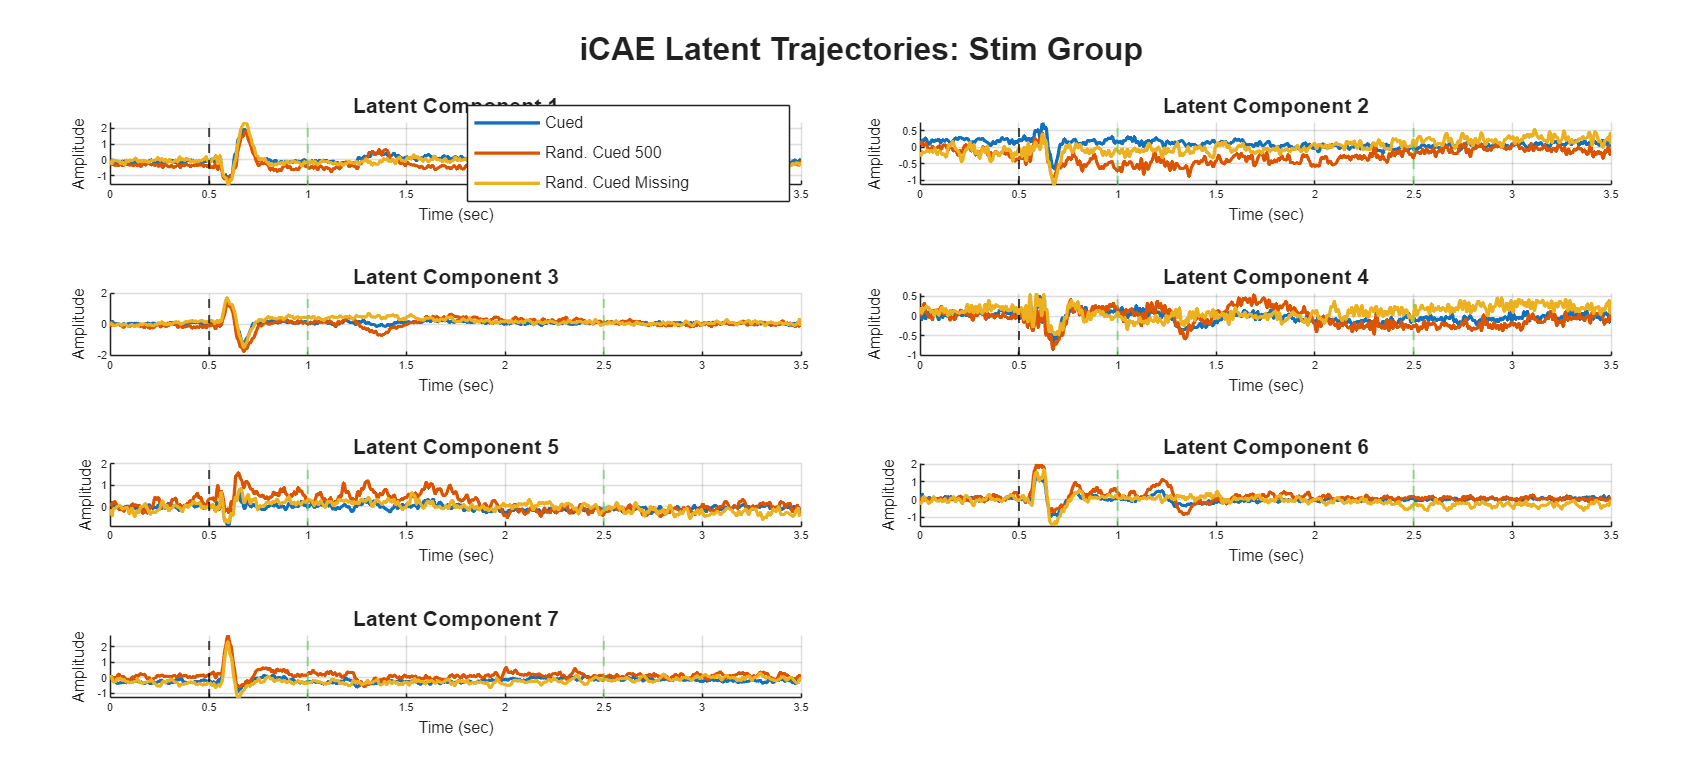

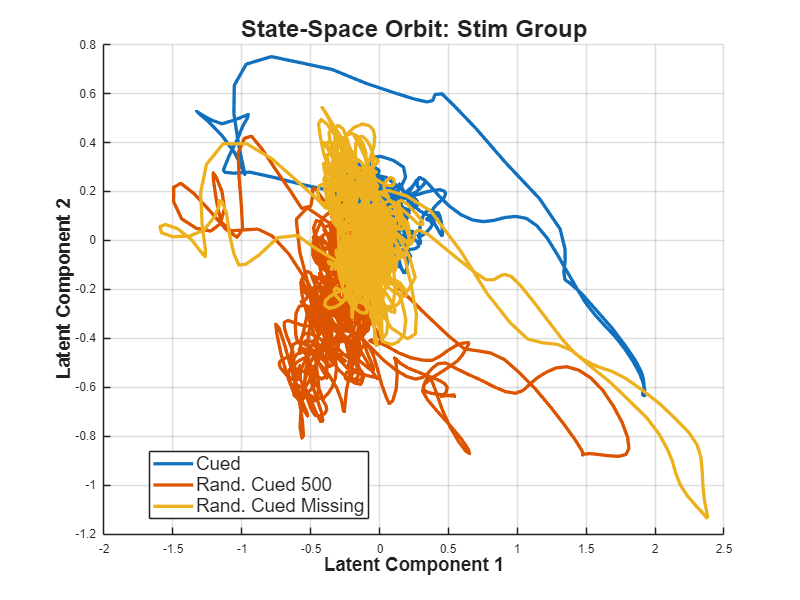

Finished Group: Stim



nTime = length(time_ms_eeg);

% Define the groups with all 3 conditions combined per group
compare_groups = struct();
compare_groups.MS   = {'BLA', 'BLT', 'P1'};
compare_groups.Temp = {'P1', 'P2_500', 'P2_2000'};
compare_groups.Stim = {'P1', 'P3_500', 'P3_missing'};

group_names = fieldnames(compare_groups);

% Master structure to save all trajectories and networks for later analysis
iCAE_results = struct(); 

for g = 1:length(group_names)
    group = group_names{g};
    target_conds = compare_groups.(group); % Now pulls all 3 conditions at once
    numClasses = length(target_conds);
    
    fprintf('\n======================================================\n');
    fprintf('Running 3-Class iCAE for Group: %s\n', group);
    fprintf('Conditions included: %s\n', strjoin(target_conds, ', '));
    fprintf('======================================================\n');
    
    %% 3.1 Prepare 4D Tensors for the Current Group
    X_list = {};
    C_list = {};

    for i = 1:numClasses
        cond = target_conds{i};
        % Concatenate all subjects' trials into [Channels x Time x TotalTrials]
        cond_data = cat(3, data_all_conds.(cond){:}); 
        num_trials = size(cond_data, 3);
        
        % FORMAT X: [1 x Time x Channels x Trials]
        X_4D = permute(cond_data, [4, 2, 1, 3]); 
        X_list{i} = X_4D;
        
        % FORMAT C (One-Hot): [1 x Time x Classes x Trials]
        C_4D = zeros(1, nTime, numClasses, num_trials);
        C_4D(1, :, i, :) = 1; % Set the current class to 1 across all time points
        C_list{i} = C_4D;
    end

    % Combine all conditions together
    X_concat = cat(4, X_list{:});
    C_concat = cat(4, C_list{:});

    % Split into 80% Train and 20% Test
    total_trials = size(X_concat, 4);
    rng(42); % For reproducibility
    idx_rand = randperm(total_trials);
    train_idx = idx_rand(1:floor(0.8*total_trials));
    test_idx = idx_rand(floor(0.8*total_trials)+1:end);

    X_train_4D = X_concat(:, :, :, train_idx);
    C_train_4D = C_concat(:, :, :, train_idx);
    X_test_4D  = X_concat(:, :, :, test_idx);
    C_test_4D  = C_concat(:, :, :, test_idx);

    fprintf('Training Tensor Size: %d x %d x %d x %d\n', size(X_train_4D));

    %% 3.2 Determine Intrinsic Dimensionality (MP & MAP Tests)
    % Reshape to 2D [Channels x (Time*Trials)] for PCA/Covariance math
    X_iCAE_input = permute(X_train_4D, [3, 2, 4, 1]);
    X_iCAE_input = reshape(X_iCAE_input, num_ch, []);

    % Velicer's MAP Test
    [num_factors, map_values] = velicer_map(X_iCAE_input');
    
    %% 3.3 Configure and Train iCAE
    cfg = struct();
    cfg.method = "icae"; 
    cfg.bottleneckSize = num_factors; % Dynamic bottleneck based on the 3 conditions!
    fprintf('Setting iCAE bottleneck size to %d based on Velicer''s MAP Test.\n', cfg.bottleneckSize);

    cfg.epochs = 200;
    cfg.batchSize = 128;
    cfg.learnRate = 1e-4; % Kept low for stability
    cfg.patience = 20;
    cfg.beta = 0.05;        
    cfg.warmupEpochs = 20;  

    disp('Training Identifiable Convolutional Autoencoder (iCAE)...');
    [encNet, decNet, priorNet, info] = trainEEG_iCAE(X_train_4D, C_train_4D, X_test_4D, C_test_4D, cfg);
    
    % Save networks to master structure under the group name
    iCAE_results.(group).encNet = encNet;
    iCAE_results.(group).info = info;

    %% 4.0 Extract and Plot Latent Trajectories (dPCA Equivalent)
    disp('Extracting Latent Trajectories for Grand Averages...');

    Z_trajectories = struct();
    colors = lines(numClasses); % Will generate 3 distinct colors

    % Create dynamic figure name
    fig_name_1D = sprintf('iCAE Latent Trajectories: %s Group', group);
    figure('Name', fig_name_1D, 'Position', [100, 100, 1800, 800]);
    
    % Safely handle grid layout based on dynamic bottleneck size
    num_rows = max(1, ceil(cfg.bottleneckSize/2));
    t = tiledlayout(num_rows, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(t, fig_name_1D, 'FontSize', 24, 'FontWeight', 'bold', 'Interpreter', 'none');

    for i = 1:numClasses
        cond = target_conds{i};
        
        % 1. Get the 2D Grand Average [Channels x Time]
        avg_data = data_grand_avg.(cond); 
        
        % 2. Reshape to 4D for the network: [1 x Time x Channels x 1]
        X_avg_4D = reshape(avg_data.', 1, nTime, num_ch, 1);
        
        % 3. Create the condition label for the average (3-classes)
        C_avg_4D = zeros(1, nTime, numClasses, 1);
        C_avg_4D(1, :, i, 1) = 1;
        
        % 4. Pass through the trained Encoder
        XC_dl = cat(3, dlarray(X_avg_4D, 'SSCB'), dlarray(C_avg_4D, 'SSCB'));
        [Z_mu_dl, ~] = forward(encNet, XC_dl);
        
        % 5. Extract data
        Z_traj = squeeze(extractdata(Z_mu_dl)); 
        
        if size(Z_traj, 2) == nTime
            Z_traj = Z_traj';
        end
        
        Z_trajectories.(cond) = Z_traj;
    end
    
    iCAE_results.(group).Z_trajectories = Z_trajectories;

    % --- Plot 1D Trajectories over Time ---
    for b = 1:cfg.bottleneckSize
        nexttile; hold on;
        for i = 1:numClasses
            cond = target_conds{i};
            
            % --- USER FRIENDLY NAME MAPPING ---
            if contains(cond, 'BLA')
                plot_name = 'Auditory';
            elseif contains(cond, 'BLT')
                plot_name = 'Tactile';
            elseif strcmp(cond, 'P1')
                plot_name = 'Cued';
            elseif contains(cond, 'P2_500')
                plot_name = 'Unpred. 500';
            elseif contains(cond, 'P2_2000')
                plot_name = 'Unpred. 2000';
            elseif contains(cond, 'P3_500')
                plot_name = 'Rand. Cued 500';
            elseif contains(cond, 'P3_missing')
                plot_name = 'Rand. Cued Missing';
            else
                plot_name = cond; % Fallback just in case
            end
            % ----------------------------------
            
            % Plot using the new friendly 'plot_name' for the Legend
            plot(time_ms_eeg, Z_trajectories.(cond)(:, b), 'Color', colors(i,:), 'LineWidth', 2.5, 'DisplayName', plot_name);
        end
        
        xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility','off'); % Primary Stimulus onset
        
        % Add P2/P3 specific late-stimulus lines if applicable
        if any(contains(target_conds, 'P2_2000')) || any(contains(target_conds, 'P3_missing'))
            xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 1.5, 'HandleVisibility','off'); 
        end
        if any(contains(target_conds, 'P2_500')) || any(contains(target_conds, 'P3_500'))
            xline(1.0, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 1.5, 'HandleVisibility','off'); 
        end
        
        title(sprintf('Latent Component %d', b), 'FontSize', 16);
        xlabel('Time (sec)', 'FontSize', 12); 
        ylabel('Amplitude', 'FontSize', 12);
        grid on;
        
        if b == 1
            legend('Location', 'best', 'FontSize', 12, 'Interpreter', 'none');
        end
        hold off;
    end

    %% 4.1 State-Space Trajectory Analysis (Latent 1 vs Latent 2)
    if cfg.bottleneckSize >= 2
        fig_name_2D = sprintf('State-Space Orbit: %s Group', group);
        figure('Name', fig_name_2D, 'Position', [150, 150, 800, 600]);
        hold on;

        for i = 1:numClasses
            cond = target_conds{i};
            Z_traj = Z_trajectories.(cond);
            
            % --- USER FRIENDLY NAME MAPPING ---
            if contains(cond, 'BLA')
                plot_name = 'Auditory';
            elseif contains(cond, 'BLT')
                plot_name = 'Tactile';
            elseif strcmp(cond, 'P1')
                plot_name = 'Cued';
            elseif contains(cond, 'P2_500')
                plot_name = 'Unpred. 500';
            elseif contains(cond, 'P2_2000')
                plot_name = 'Unpred. 2000';
            elseif contains(cond, 'P3_500')
                plot_name = 'Rand. Cued 500';
            elseif contains(cond, 'P3_missing')
                plot_name = 'Rand. Cued Missing';
            else
                plot_name = cond;
            end
            % ----------------------------------
            
            % Plot Latent 1 on X-axis, Latent 2 on Y-axis
            plot(Z_traj(:, 1), Z_traj(:, 2), 'Color', colors(i,:), 'LineWidth', 2.5, 'DisplayName', plot_name);
            
            % Mark Start (Circle) and End (X)
            scatter(Z_traj(1, 1), Z_traj(1, 2), 120, colors(i,:), 'filled', 'o', 'HandleVisibility', 'off'); 
            scatter(Z_traj(end, 1), Z_traj(end, 2), 150, colors(i,:), 'x', 'LineWidth', 3, 'HandleVisibility', 'off'); 
        end

        xlabel('Latent Component 1', 'FontSize', 14, 'FontWeight', 'bold'); 
        ylabel('Latent Component 2', 'FontSize', 14, 'FontWeight', 'bold');
        title(fig_name_2D, 'FontSize', 18, 'Interpreter', 'none');
        legend('Location', 'best', 'FontSize', 14, 'Interpreter', 'none');
        grid on; hold off;
    end
    
    fprintf('Finished Group: %s\n\n', group);
end

disp('All 3-Class iCAE Comparisons Complete!');

All 3-Class iCAE Comparisons Complete!


## 5.3.0 Define ALL Conditions for Global iCAE

disp('Initializing Global iCAE (All Conditions Simultaneously)...');

Initializing Global iCAE (All Conditions Simultaneously)...


nTime = length(time_ms_eeg);

% Define the groups (we will use these later just to organize the plots)
compare_groups = struct();
compare_groups.MS   = {'BLA', 'BLT', 'P1'};
compare_groups.Temp = {'P1', 'P2_500', 'P2_2000'};
compare_groups.Stim = {'P1', 'P3_500', 'P3_missing'};

group_names = fieldnames(compare_groups);

% Extract all unique conditions across all groups to train ONE global model
all_conds = {'BLA', 'BLT', 'P1', 'P2_500', 'P2_2000', 'P3_500', 'P3_missing'};
numClasses = length(all_conds);

fprintf('\n======================================================\n');

fprintf('Running %d-Class Global iCAE\n', numClasses);

Running 7-Class Global iCAE


fprintf('Conditions included: %s\n', strjoin(all_conds, ', '));

Conditions included: BLA, BLT, P1, P2_500, P2_2000, P3_500, P3_missing


fprintf('======================================================\n');


%% 3.1 Prepare 4D Tensors for the Global Dataset
X_list = cell(1, numClasses);
C_list = cell(1, numClasses);

for i = 1:numClasses
    cond = all_conds{i};
    
    % Concatenate all subjects' trials into [Channels x Time x TotalTrials]
    cond_data = cat(3, data_all_conds.(cond){:}); 
    num_trials = size(cond_data, 3);
    
    % FORMAT X: [1 x Time x Channels x Trials]
    X_list{i} = permute(cond_data, [4, 2, 1, 3]); 
    
    % FORMAT C (One-Hot): [1 x Time x 7 Classes x Trials]
    C_4D = zeros(1, nTime, numClasses, num_trials, 'single');
    C_4D(1, :, i, :) = 1; % Set the current class index to 1
    C_list{i} = C_4D;
end

% Combine all conditions together into one massive tensor
X_train_4D_full = single(cat(4, X_list{:}));
C_train_4D_full = single(cat(4, C_list{:}));

% Split into 80% Train and 20% Test
total_trials = size(X_train_4D_full, 4);
rng(42); % For reproducibility
idx_rand = randperm(total_trials);
val_split = floor(0.8 * total_trials);

X_train_4D = X_train_4D_full(:, :, :, idx_rand(1:val_split));
C_train_4D = C_train_4D_full(:, :, :, idx_rand(1:val_split));
X_test_4D  = X_train_4D_full(:, :, :, idx_rand(val_split+1:end));
C_test_4D  = C_train_4D_full(:, :, :, idx_rand(val_split+1:end));

% Clear massive temporary variables
clear X_train_4D_full C_train_4D_full X_list C_list;

fprintf('Global Training Tensor Size: %d x %d x %d x %d\n', size(X_train_4D));

Global Training Tensor Size: 1 x 1792 x 32 x 3360



%% 3.2 Determine Intrinsic Dimensionality (MP & MAP Tests)
disp('Calculating Global Intrinsic Dimensionality...');

Calculating Global Intrinsic Dimensionality...


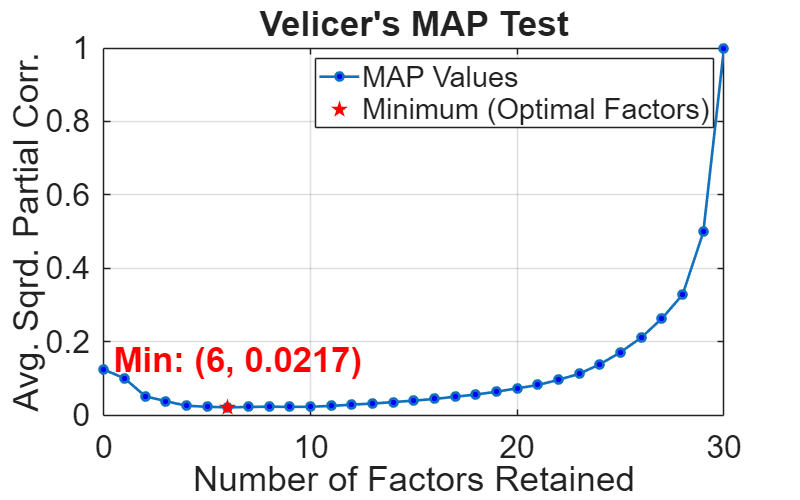

Velicer's MAP Test recommends retaining 6 factors.



% Reshape to 2D [Channels x (Time*Trials)] for PCA/Covariance math
X_iCAE_input = permute(X_train_4D, [3, 2, 4, 1]);
X_iCAE_input = reshape(X_iCAE_input, num_ch, []);

% Velicer's MAP Test (Cast to double to prevent precision errors in cov)
[num_factors, map_values] = velicer_map(double(X_iCAE_input'));


%% 3.3 Configure and Train the Global iCAE
cfg = struct();
cfg.method = "icae"; 
cfg.bottleneckSize = num_factors; % Dynamic global bottleneck!
fprintf('Setting iCAE bottleneck size to %d based on Velicer''s MAP Test.\n', cfg.bottleneckSize);

Setting iCAE bottleneck size to 6 based on Velicer's MAP Test.



cfg.epochs = 200;
cfg.batchSize = 128;
cfg.learnRate = 1e-4; 
cfg.patience = 20;
cfg.beta = 0.05;        
cfg.warmupEpochs = 20;  
cfg.verbose = true;

disp('Training Global Identifiable Convolutional Autoencoder (iCAE)...');

Training Global Identifiable Convolutional Autoencoder (iCAE)...


[encNet, decNet, priorNet, info] = trainEEG_iCAE(X_train_4D, C_train_4D, X_test_4D, C_test_4D, cfg);

Epoch 1/200 (Beta: 0.0000) - Train Loss: 73.8874 | Val Loss: 49.5579
Epoch 2/200 (Beta: 0.0026) - Train Loss: 44.0286 | Val Loss: 40.1654
Epoch 3/200 (Beta: 0.0053) - Train Loss: 39.1987 | Val Loss: 37.1120
Epoch 4/200 (Beta: 0.0079) - Train Loss: 37.4425 | Val Loss: 35.5631
Epoch 5/200 (Beta: 0.0105) - Train Loss: 36.6047 | Val Loss: 35.1096
Epoch 6/200 (Beta: 0.0132) - Train Loss: 35.8385 | Val Loss: 34.9054
Epoch 7/200 (Beta: 0.0158) - Train Loss: 36.0399 | Val Loss: 34.7131
Epoch 8/200 (Beta: 0.0184) - Train Loss: 35.6923 | Val Loss: 34.6095
Epoch 9/200 (Beta: 0.0211) - Train Loss: 35.6140 | Val Loss: 34.5925
Epoch 10/200 (Beta: 0.0237) - Train Loss: 35.1431 | Val Loss: 34.4538
Epoch 11/200 (Beta: 0.0263) - Train Loss: 35.2470 | Val Loss: 34.3605
Epoch 12/200 (Beta: 0.0289) - Train Loss: 35.0692 | Val Loss: 34.3153
Epoch 13/200 (Beta: 0.0316) - Train Loss: 34.9594 | Val Loss: 34.2018
Epoch 14/200 (Beta: 0.0342) - Train Loss: 34.7456 | Val Loss: 34.1195
Epoch 15/200 (Beta: 0.0368) -


% Master structure to save trajectories and network
global_iCAE_results = struct(); 
global_iCAE_results.encNet = encNet;
global_iCAE_results.info = info;


## 4.0 Extract Latent Trajectories for ALL Conditions


disp('Extracting Universal Latent Trajectories for Grand Averages...');

Extracting Universal Latent Trajectories for Grand Averages...



Z_trajectories = struct();

for i = 1:numClasses
    cond = all_conds{i};
    
    % 1. Get the 2D Grand Average [Channels x Time]
    avg_data = data_grand_avg.(cond); 
    
    % 2. Reshape to 4D for the network: [1 x Time x Channels x 1]
    X_avg_4D = reshape(avg_data.', 1, nTime, num_ch, 1);
    
    % 3. Create the condition label for the average (7-classes)
    C_avg_4D = zeros(1, nTime, numClasses, 1, 'single');
    C_avg_4D(1, :, i, 1) = 1;
    
    % 4. Pass through the trained Encoder
    XC_dl = cat(3, dlarray(single(X_avg_4D), 'SSCB'), dlarray(C_avg_4D, 'SSCB'));
    [Z_mu_dl, ~] = forward(encNet, XC_dl);
    
    % 5. Extract data
    Z_traj = squeeze(extractdata(Z_mu_dl)); 
    
    if size(Z_traj, 2) == nTime
        Z_traj = Z_traj';
    end
    
    Z_trajectories.(cond) = Z_traj;
end

global_iCAE_results.Z_trajectories = Z_trajectories;


## 4.1 Plot Trajectories Separated by Cognitive Group

Plotting Universal Components for Group: MS


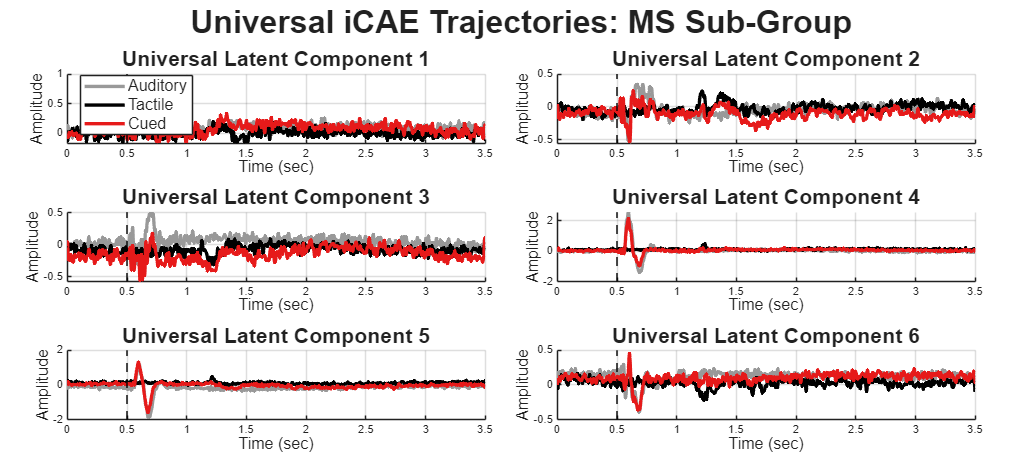

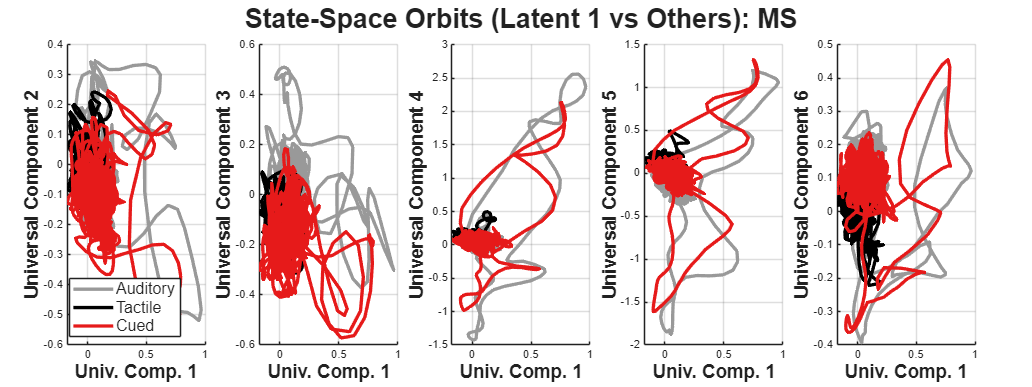

Plotting Universal Components for Group: Temp


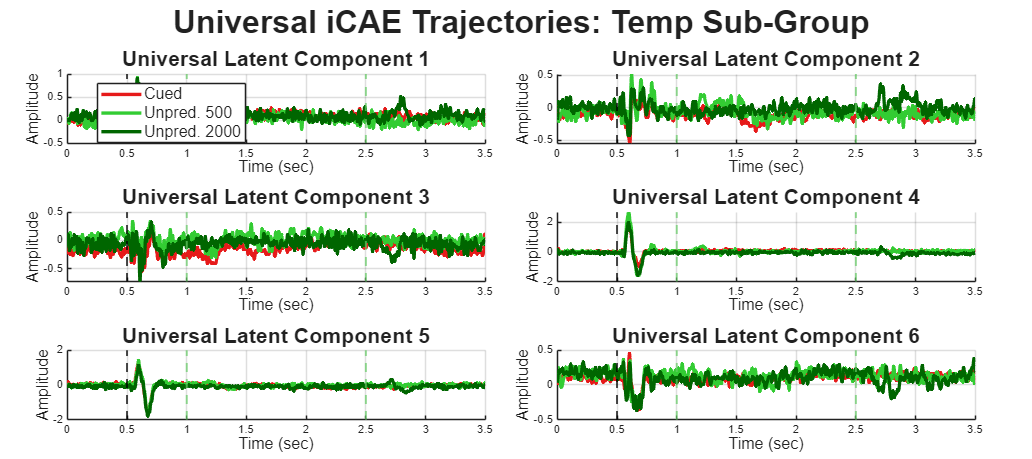

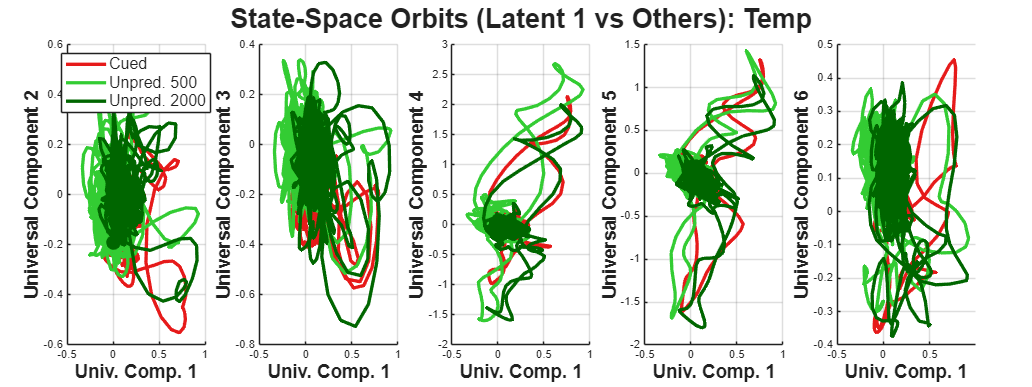

Plotting Universal Components for Group: Stim


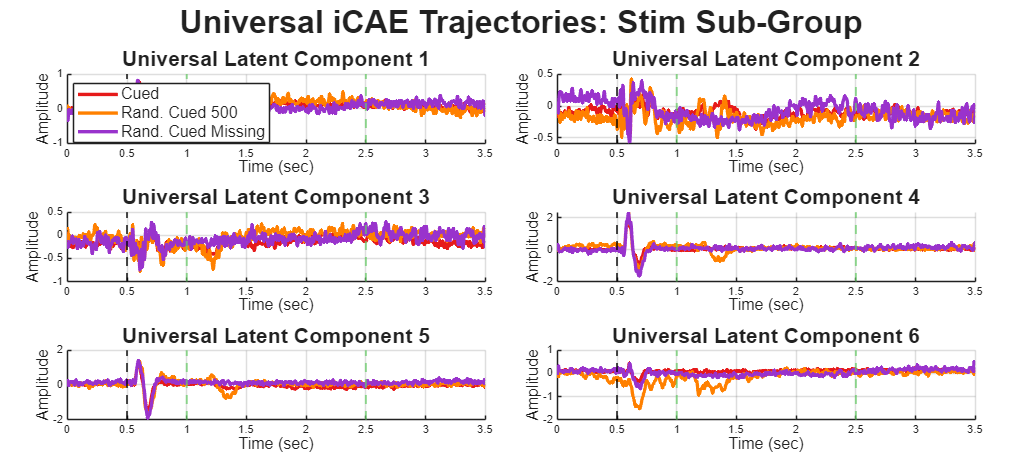

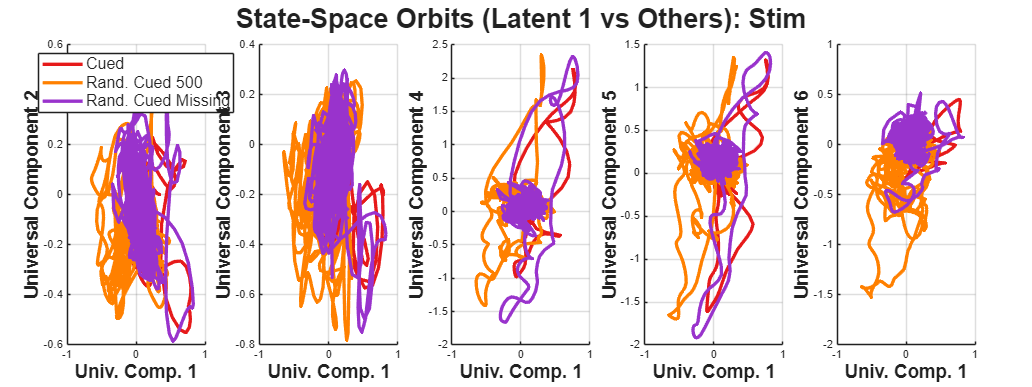

%% 4.1 Plot Trajectories Separated by Cognitive Group
% We loop through the groups to plot them clearly, but they are all
% drawn from the exact same universal latent space!

friendly_names = @(x) strrep(strrep(strrep(strrep(strrep(strrep(strrep(x, ...
    'P2_500', 'Unpred. 500'), 'P2_2000', 'Unpred. 2000'), 'P3_500', 'Rand. Cued 500'), ...
    'P3_missing', 'Rand. Cued Missing'), 'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued');

color_map = struct('BLA', [0.6 0.6 0.6], 'BLT', [0.0 0.0 0.0], 'P1', [0.9 0.1 0.1], ...
    'P2_500', [0.2 0.8 0.2], 'P2_2000', [0.0 0.4 0.0], 'P3_500', [1.0 0.5 0.0], 'P3_missing', [0.6 0.2 0.8]);

for g = 1:length(group_names)
    group = group_names{g};
    target_conds = compare_groups.(group);
    
    fprintf('Plotting Universal Components for Group: %s\n', group);
    
    % =====================================================================
    % FIGURE 1: 1D Trajectories over Time
    % =====================================================================
    fig_name_1D = sprintf('Universal iCAE Trajectories: %s Sub-Group', group);
    figure('Name', fig_name_1D, 'Position', [100, 100, 1800, 800]);
    
    num_rows = max(1, ceil(cfg.bottleneckSize/2));
    t = tiledlayout(num_rows, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(t, fig_name_1D, 'FontSize', 24, 'FontWeight', 'bold', 'Interpreter', 'none');

    for b = 1:cfg.bottleneckSize
        nexttile; hold on;
        for i = 1:length(target_conds)
            cond = target_conds{i};
            plot_name = friendly_names(cond);
            if isfield(color_map, cond), clr = color_map.(cond); else, clr = rand(1,3); end
            
            % Plot using the extracted universal trajectories
            plot(time_ms_eeg, Z_trajectories.(cond)(:, b), 'Color', clr, 'LineWidth', 2.5, 'DisplayName', plot_name);
        end
        
        xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility','off'); % Primary Stimulus onset
        
        if any(contains(target_conds, 'P2_2000')) || any(contains(target_conds, 'P3_missing'))
            xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 1.5, 'HandleVisibility','off'); 
        end
        if any(contains(target_conds, 'P2_500')) || any(contains(target_conds, 'P3_500'))
            xline(1.0, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 1.5, 'HandleVisibility','off'); 
        end
        
        title(sprintf('Universal Latent Component %d', b), 'FontSize', 16);
        xlabel('Time (sec)', 'FontSize', 12); 
        ylabel('Amplitude', 'FontSize', 12);
        grid on;
        
        if b == 1
            legend('Location', 'best', 'FontSize', 12, 'Interpreter', 'none');
        end
        hold off;
    end

    % =====================================================================
    % FIGURE 2: Multi-Orbit State-Space Analysis (Latent 1 vs Latent N)
    % =====================================================================
    if cfg.bottleneckSize >= 2
        fig_name_2D = sprintf('Universal State-Space Orbits: %s Sub-Group', group);
        figure('Name', fig_name_2D, 'Position', [150, 150, 1600, 600]); % Wider figure to accommodate subplots
        
        % Calculate layout for Latent 1 vs (Latent 2 through N)
        num_orbits = cfg.bottleneckSize - 1;
        t2 = tiledlayout(1, num_orbits, 'TileSpacing', 'compact', 'Padding', 'compact');
        title(t2, sprintf('State-Space Orbits (Latent 1 vs Others): %s', group), 'FontSize', 20, 'FontWeight', 'bold', 'Interpreter', 'none');
        
        for b = 2:cfg.bottleneckSize
            nexttile; hold on;
            
            for i = 1:length(target_conds)
                cond = target_conds{i};
                Z_traj = Z_trajectories.(cond);
                plot_name = friendly_names(cond);
                if isfield(color_map, cond), clr = color_map.(cond); else, clr = rand(1,3); end
                
                % Plot Latent 1 on X-axis, Latent 'b' on Y-axis
                plot(Z_traj(:, 1), Z_traj(:, b), 'Color', clr, 'LineWidth', 2.5, 'DisplayName', plot_name);
                
                % Mark Start (Circle) and End (X)
                scatter(Z_traj(1, 1), Z_traj(1, b), 120, clr, 'filled', 'o', 'HandleVisibility', 'off'); 
                scatter(Z_traj(end, 1), Z_traj(end, b), 150, clr, 'x', 'LineWidth', 3, 'HandleVisibility', 'off'); 
            end
            
            xlabel('Univ. Comp. 1', 'FontSize', 14, 'FontWeight', 'bold'); 
            ylabel(sprintf('Universal Component %d', b), 'FontSize', 14, 'FontWeight', 'bold');
            grid on; hold off;
            
            % Only show legend on the first orbit subplot
            if b == 2
                legend('Location', 'best', 'FontSize', 12, 'Interpreter', 'none');
            end
        end
    end
end

disp('Global iCAE Analysis Complete!');

Global iCAE Analysis Complete!


## 5.3 iCAE Leave-One-Subject-Out (LOSO) Training & Projection

%% 5.3 Global iCAE Leave-One-Subject-Out (LOSO) Training & Projection
disp('Initializing Global iCAE LOSO Loop (Universal Manifold)...');

Initializing Global iCAE LOSO Loop (Universal Manifold)...



nTime = length(time_ms_eeg);
cfg = struct();
cfg.method = "icae"; 
cfg.bottleneckSize = 4; % LOCKED for cross-subject consistency
cfg.epochs = 150;       % Slightly reduced for LOSO speed
cfg.batchSize = 128;
cfg.learnRate = 1e-4;
cfg.patience = 15;
cfg.beta = 0.05;        
cfg.warmupEpochs = 20;  
cfg.verbose = false;    % Silences terminal spam from the workers

% Define the downstream groups for later sorting
compare_groups = struct();
compare_groups.MS   = {'BLA', 'BLT', 'P1'};
compare_groups.Temp = {'P1', 'P2_500', 'P2_2000'};
compare_groups.Stim = {'P1', 'P3_500', 'P3_missing'};
group_names = fieldnames(compare_groups);

% Extract ALL unique conditions for the Global Model (7 Classes)
all_conds = {'BLA', 'BLT', 'P1', 'P2_500', 'P2_2000', 'P3_500', 'P3_missing'};
numClasses = length(all_conds);

cond_names = fieldnames(data_all_conds);
num_subjs = length(data_all_conds.(cond_names{1}));

fprintf('\n======================================================\n');

fprintf('Running %d-Class GLOBAL LOSO iCAE\n', numClasses);

Running 7-Class GLOBAL LOSO iCAE


fprintf('Conditions: %s\n', strjoin(all_conds, ', '));

Conditions: BLA, BLT, P1, P2_500, P2_2000, P3_500, P3_missing


fprintf('======================================================\n');


% --- ANTI-DESERIALIZATION CRASH FIX ---
% Extract the global data before parfor to prevent broadcasting massive structs
global_data = cell(numClasses, num_subjs);
for i = 1:numClasses
    global_data(i, :) = data_all_conds.(all_conds{i});
end

% --- PARFOR SLICING FIX ---
% Flat tensor for all 7 conditions: [Subjects x Time x Latents x 7]
Z_loso_flat = nan(num_subjs, nTime, cfg.bottleneckSize, numClasses);

parfor s = 1:num_subjs
    fprintf('  Worker running Fold %d/%d (Excluding Subject %d)...\n', s, num_subjs, s);
    
    other_subjs = setdiff(1:num_subjs, s);
    
    %% 5.1 Prepare 4D Tensors for the N-1 Subjects (Training)
    X_list = cell(1, numClasses);
    C_list = cell(1, numClasses);
    
    for i = 1:numClasses
        % Use isolated global data
        cond_data = cat(3, global_data{i, other_subjs}); 
        num_trials = size(cond_data, 3);
        
        X_list{i} = permute(cond_data, [4, 2, 1, 3]); 
        
        % Pre-cast C to single to save memory immediately
        C_4D = zeros(1, nTime, numClasses, num_trials, 'single');
        C_4D(1, :, i, :) = 1; 
        C_list{i} = C_4D;
    end

    X_train_4D_full = cat(4, X_list{:});
    C_train_4D_full = cat(4, C_list{:});
    
    % Split Train/Validation
    num_total_trials = size(X_train_4D_full, 4);
    idx_rand = randperm(num_total_trials);
    val_split = floor(0.9 * num_total_trials);
    
    % --- MEMORY FIX: Cast X to single precision to cut RAM usage by 50% ---
    X_val_4D   = single(X_train_4D_full(:, :, :, idx_rand(val_split+1:end)));
    C_val_4D   = C_train_4D_full(:, :, :, idx_rand(val_split+1:end));
    X_train_4D = single(X_train_4D_full(:, :, :, idx_rand(1:val_split)));
    C_train_4D = C_train_4D_full(:, :, :, idx_rand(1:val_split));
    
    % --- WORKER MEMORY FLUSH ---
    X_train_4D_full = []; C_train_4D_full = []; X_list = {}; C_list = {};

    %% 5.2 Train the Global Fold's iCAE
    [encNet_loso, ~, ~, ~] = trainEEG_iCAE(X_train_4D, C_train_4D, X_val_4D, C_val_4D, cfg); 

    %% 5.3 Project the Excluded Subject into the Universal Latent Space
    temp_Z_subj = nan(1, nTime, cfg.bottleneckSize, numClasses);
    
    for i = 1:numClasses
        % Average the left-out subject's trials
        subj_avg = mean(global_data{i, s}, 3, 'omitnan');
        
        if all(isnan(subj_avg(:))), continue; end
        
        X_subj_4D = reshape(subj_avg.', 1, nTime, size(subj_avg,1), 1);
        C_subj_4D = zeros(1, nTime, numClasses, 1, 'single');
        C_subj_4D(1, :, i, 1) = 1;
        
        XC_dl = cat(3, dlarray(single(X_subj_4D), 'SSCB'), dlarray(C_subj_4D, 'SSCB'));
        [Z_mu_dl, ~] = forward(encNet_loso, XC_dl);
        
        Z_traj = squeeze(extractdata(Z_mu_dl)); 
        if size(Z_traj, 2) == nTime, Z_traj = Z_traj'; end 
        
        temp_Z_subj(1, :, :, i) = Z_traj;
    end
    Z_loso_flat(s, :, :, :) = temp_Z_subj;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
  Worker running Fold 4/14 (Excluding Subject 4)...
  Worker running Fold 8/14 (Excluding Subject 8)...
  Worker running Fold 5/14 (Excluding Subject 5)...
  Worker running Fold 7/14 (Excluding Subject 7)...
  Worker running Fold 3/14 (Excluding Subject 3)...
  Worker running Fold 1/14 (Excluding Subject 1)...
  Worker running Fold 6/14 (Excluding Subject 6)...
  Worker running Fold 2/14 (Excluding Subject 2)...
  Worker running Fold 12/14 (Excluding Subject 12)...
  Worker running Fold 9/14 (Excluding Subject 9)...
  Worker running Fold 10/14 (Excluding Subject 10)...
  Worker running Fold 14/14 (Excluding Subject 14)...
  Worker running Fold 13/14 (Excluding Subject 13)...
  Worker running Fold 11/14 (Excluding Subject 11)...


% --- FLUSH MASTER MEMORY SAFELY ---
% Replaced 'clear' with empty assignment to prevent MATLAB JIT scope errors
global_data = [];


## 5.4 Map Universal Trajectories Back into Sub-Groups

%% 5.4 Map Universal Trajectories Back into Sub-Groups
    % This allows your downstream plotting and ANOVA scripts to function perfectly!
    Z_loso = struct();

    for g = 1:length(group_names)
        group = group_names{g};
        target_conds = compare_groups.(group);
        
        % Allocate group specific sub-tensor [Subjs x Time x Latents x 3]
        Z_loso.(group) = nan(num_subjs, nTime, cfg.bottleneckSize, length(target_conds));
        
        for i = 1:length(target_conds)
            cond = target_conds{i};
            % Find where this condition lives in the 7-class global array
            global_idx = find(strcmp(all_conds, cond));
            
            % Copy just that trajectory into the downstream group struct
            Z_loso.(group)(:, :, :, i) = Z_loso_flat(:, :, :, global_idx);
        end
    end

    % Free memory safely
    Z_loso_flat = []; 
    disp('Global LOSO iCAE Complete & Successfully Mapped to Sub-Groups!');

Global LOSO iCAE Complete & Successfully Mapped to Sub-Groups!


## 6.0 Plot LOSO ERPs (Mean ± 1 SD) in Latent Space

disp('Plotting Latent ERPs...');

Plotting Latent ERPs...


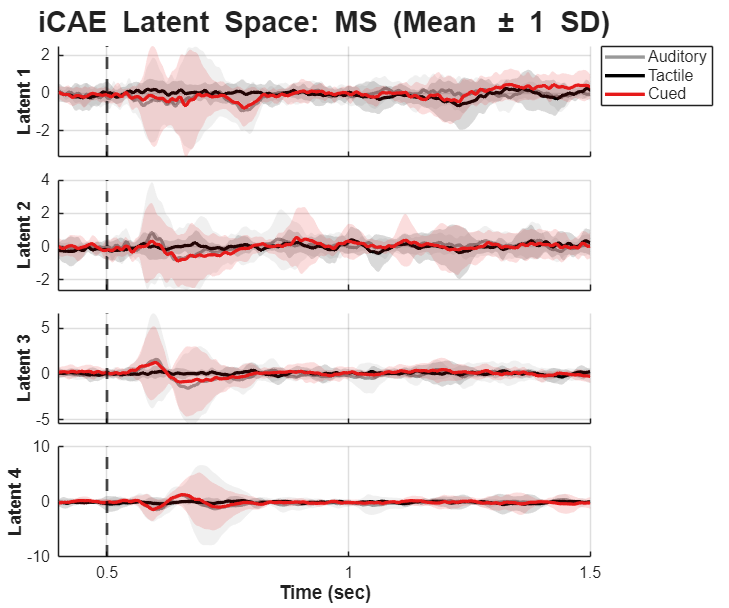

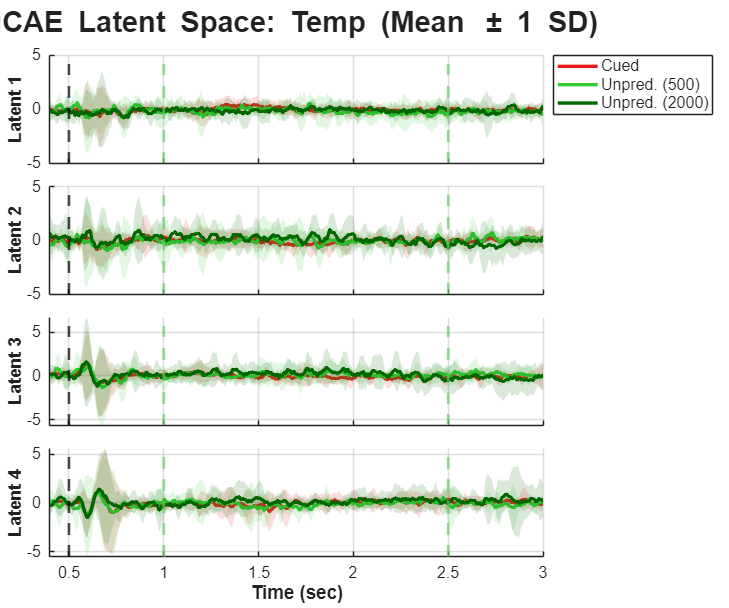

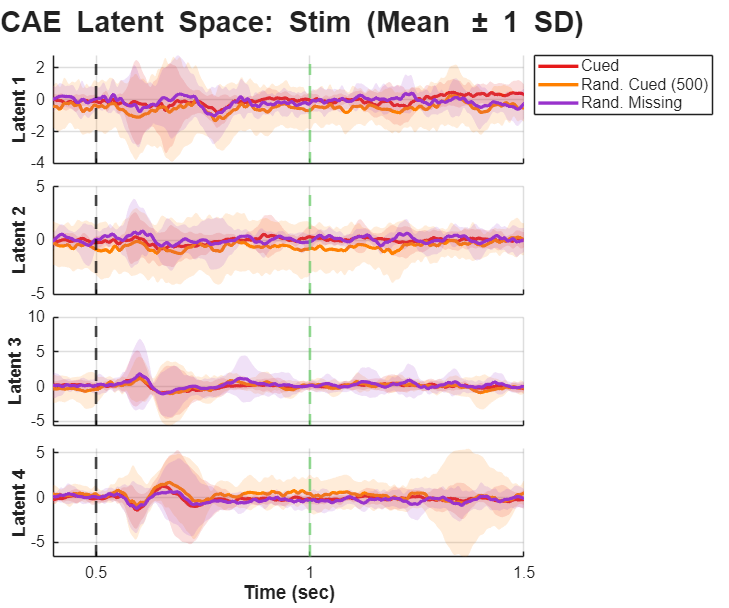


friendly_names = @(x) strrep(strrep(strrep(strrep(strrep(strrep(strrep(x, ...
    'P2_500', 'Unpred. (500)'), 'P2_2000', 'Unpred. (2000)'), 'P3_500', 'Rand. Cued (500)'), ...
    'P3_missing', 'Rand. Missing'), 'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued');

color_map = struct('BLA', [0.6 0.6 0.6], 'BLT', [0.0 0.0 0.0], 'P1', [0.9 0.1 0.1], ...
    'P2_500', [0.2 0.8 0.2], 'P2_2000', [0.0 0.4 0.0], 'P3_500', [1.0 0.5 0.0], 'P3_missing', [0.6 0.2 0.8]);

for g = 1:length(group_names)
    group = group_names{g};
    target_conds = compare_groups.(group);
    
    figure('Position', [100, 100, 1200, 1000], 'Name', sprintf('iCAE Latent Space: %s', group));
    t = tiledlayout(cfg.bottleneckSize, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(t, sprintf('iCAE Latent Space: %s (Mean \\pm 1 SD)', group), 'FontSize', 22, 'FontWeight', 'bold');
    
    for b = 1:cfg.bottleneckSize
        nexttile; hold on;
        
        for i = 1:length(target_conds)
            cond = target_conds{i};
            c_name = friendly_names(cond);
            if isfield(color_map, cond), clr = color_map.(cond); else, clr = rand(1,3); end
            
            subj_traces = squeeze(Z_loso.(group)(:, :, b, i)); 
            
            mu = mean(subj_traces, 1, 'omitnan');
            sd = std(subj_traces, 0, 1, 'omitnan');
            
            x_patch = [time_ms_eeg, fliplr(time_ms_eeg)];
            y_patch = [mu + sd, fliplr(mu - sd)];
            patch(x_patch, y_patch, clr, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
            plot(time_ms_eeg, mu, 'Color', clr, 'LineWidth', 2.5, 'DisplayName', c_name);
        end
        
        % --- EVENT MARKERS ---
        xline(0.5, 'k--', 'LineWidth', 2, 'HandleVisibility', 'off');
        if strcmp(group, 'Temp') || strcmp(group, 'Stim')
            xline(1.0, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2, 'HandleVisibility', 'off');
        end
        if strcmp(group, 'Temp')
            % Extra marker for the 2000ms delayed condition target
            xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2, 'HandleVisibility', 'off');
        end
        
        % --- DYNAMIC X-AXIS LIMITS ---
        if strcmp(group, 'Temp')
            xlim([0.4 3.0]);
        else
            xlim([0.4 1.5]);
        end
        
        ylabel(sprintf('Latent %d', b), 'FontSize', 14, 'FontWeight', 'bold');
        grid on; set(gca, 'FontSize', 12);
        if b == 1, legend('Location', 'bestoutside', 'FontSize', 12); end
        if b == cfg.bottleneckSize, xlabel('Time (sec)', 'FontSize', 14, 'FontWeight', 'bold'); else, xticklabels({}); end
        hold off;
    end
end

disp('Latent ERP plotting complete.');

Latent ERP plotting complete.


## 7.0 Dynamic Sliding Window Cosine Similarity

%% 7.0 Dynamic Sliding Window Cosine Similarity
disp('Calculating Dynamic Cosine Similarity for Latents 1-4...');

Calculating Dynamic Cosine Similarity for Latents 1-4...


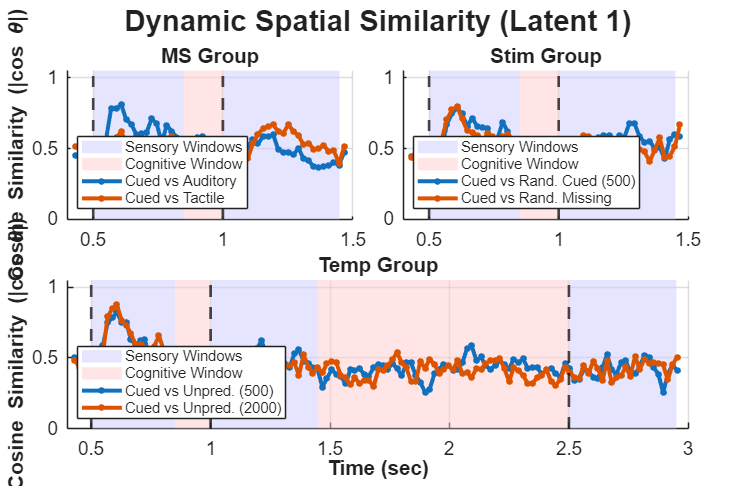

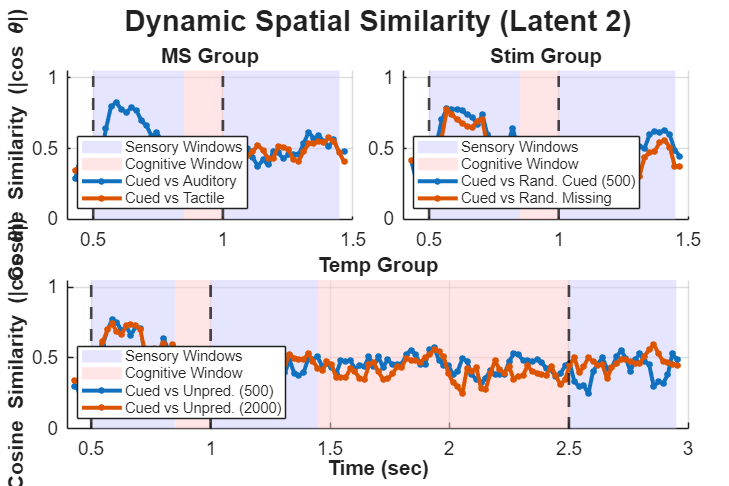

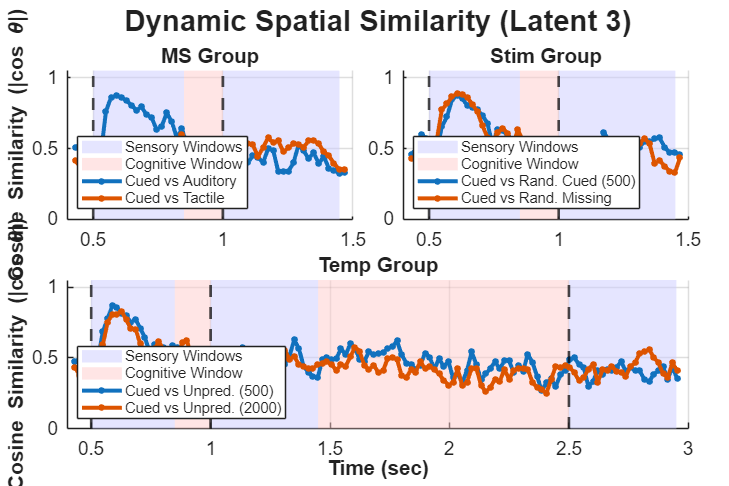

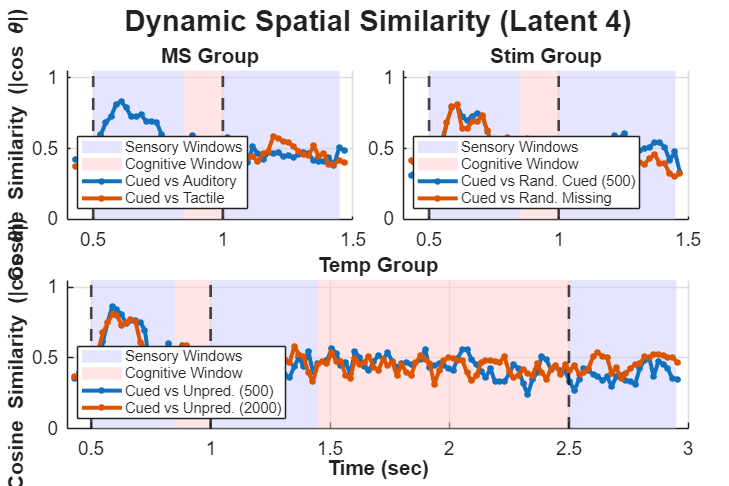


win_ms = 64; 
step_ms = 20; 
win_samples = round((win_ms / 1000) * 512); % Assuming fs = 512 Hz
step_samples = round((step_ms / 1000) * 512);

num_latents_to_plot = 4;

% Loop through the first 4 latents
for lat = 1:num_latents_to_plot
    
    % Create a 2x2 grid figure for each latent
    figure('Position', [100 + (lat*20), 100 + (lat*20), 1200, 800], ...
           'Name', sprintf('Dynamic Cosine Sim (Latent %d)', lat));
    tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    for g = 1:length(group_names)
        group = group_names{g};
        target_conds = compare_groups.(group);
        
        % --- ROUTE GROUPS TO SPECIFIC TILES ---
        if strcmp(group, 'MS')
            nexttile(1); % Top Left
        elseif strcmp(group, 'Stim')
            nexttile(2); % Top Right
        elseif strcmp(group, 'Temp')
            nexttile(3, [1 2]); % Bottom Row, Spanning both columns!
        else
            nexttile; 
        end
        hold on;
        
        % --- DYNAMIC X-AXIS EXTENSION ---
        if strcmp(group, 'Temp')
            t_start = 0.4;
            t_end   = 3.0;
        else
            t_start = 0.4;
            t_end   = 1.5;
        end
        
        valid_idx = find(time_ms_eeg >= t_start & time_ms_eeg <= t_end);
        win_starts = 1:step_samples:(length(valid_idx) - win_samples + 1);
        global_time_centers = zeros(1, length(win_starts));
        
        for w = 1:length(win_starts)
            idx = valid_idx(win_starts(w) : win_starts(w) + win_samples - 1);
            global_time_centers(w) = mean(time_ms_eeg(idx));
        end

        % Force P1 to always be the baseline comparison condition
        base_idx = find(strcmp(target_conds, 'P1'));
        if isempty(base_idx), base_idx = 1; end
        
        y_limits = [0 1.05];
        
        % STANDARD PATCHES
        patch([0.5, 0.85, 0.85, 0.5], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Sensory Windows');
        patch([1.0, 1.45, 1.45, 1.0], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        patch([0.85, 1.0, 1.0, 0.85], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [1.0 0.8 0.8], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Cognitive Window');
        
        xline(0.5, 'k--', 'LineWidth', 2, 'HandleVisibility', 'off');
        xline(1.0, 'k--', 'LineWidth', 2, 'HandleVisibility', 'off');
        
        % --- EXTENDED PATCHES FOR TEMP GROUP ---
        if strcmp(group, 'Temp')
            % Extra Cognitive Wait Window (1.45s - 2.5s)
            patch([1.45, 2.5, 2.5, 1.45], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [1.0 0.8 0.8], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off');
            
            % Extra Tactile Target Window (2.5s - 2.95s)
            patch([2.5, 2.95, 2.95, 2.5], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off');
            
            xline(2.5, 'k--', 'LineWidth', 2, 'HandleVisibility', 'off');
        end

        for c = 1:length(target_conds)
            if c == base_idx, continue; end
            
            sim_trace = nan(num_subjs, length(win_starts));
            
            for s = 1:num_subjs
                for w = 1:length(win_starts)
                    idx = valid_idx(win_starts(w) : win_starts(w) + win_samples - 1);
                    
                    % --- UPDATED: Extract 1D trajectory segment for current latent ---
                    x = squeeze(Z_loso.(group)(s, idx, lat, base_idx));
                    y = squeeze(Z_loso.(group)(s, idx, lat, c));
                    
                    if ~any(isnan(x)) && ~any(isnan(y))
                        % Real 1D Vector Absolute Cosine Similarity
                        sim_trace(s, w) = abs(dot(x, y) / (norm(x) * norm(y)));
                    end
                end
            end
            
            mu_sim = mean(sim_trace, 1, 'omitnan');
            c_name = sprintf('%s vs %s', friendly_names(target_conds{base_idx}), friendly_names(target_conds{c}));
            
            % Color logic (fallback to lines if color_map not used globally here)
            plot(global_time_centers, mu_sim, '.-', 'LineWidth', 3, 'MarkerSize', 15, 'DisplayName', c_name);
        end
        
        xlim([t_start, t_end]); ylim(y_limits); grid on;
        
        % Only label X-axis on the bottom plots
        if strcmp(group, 'Temp')
            xlabel('Time (sec)', 'FontSize', 14, 'FontWeight', 'bold');
        end
        
        % Only label Y-axis on the left plots
        if strcmp(group, 'MS') || strcmp(group, 'Temp')
            ylabel('Cosine Similarity (|cos \theta|)', 'FontSize', 14, 'FontWeight', 'bold');
        end
        
        title(sprintf('%s Group', group), 'FontSize', 16, 'FontWeight', 'bold');
        set(gca, 'FontSize', 14);
        legend('Location', 'southwest', 'FontSize', 11);
        hold off;
    end
    
    % Master Title for the Figure
    sgtitle(sprintf('Dynamic Spatial Similarity (Latent %d)', lat), 'FontSize', 22, 'FontWeight', 'bold');
end


disp('Dynamic plotting complete.');

Dynamic plotting complete.


## 8.0 Statistical Quantification: RM ANOVA & Bar Charts

disp('Running RM ANOVA on Latent Trajectory Cosine Similarity...');

Running RM ANOVA on Latent Trajectory Cosine Similarity...


  ANOVA RESULTS FOR SPACE: MS (Latent 1)


                                SumSq     DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                               _______    __    ________    _______    __________    __________    __________    __________
    (Intercept)                 15.647     1      15.647     118.06    6.8111e-08    6.8111e-08    6.8111e-08    6.8111e-08
    Error                        1.723    13     0.13254                                                                   
    (Intercept):Pair           0.21441     1     0.21441     7.2555      0.018417      0.018417      0.018417      0.018417
    Error(Pair)                0.38417  

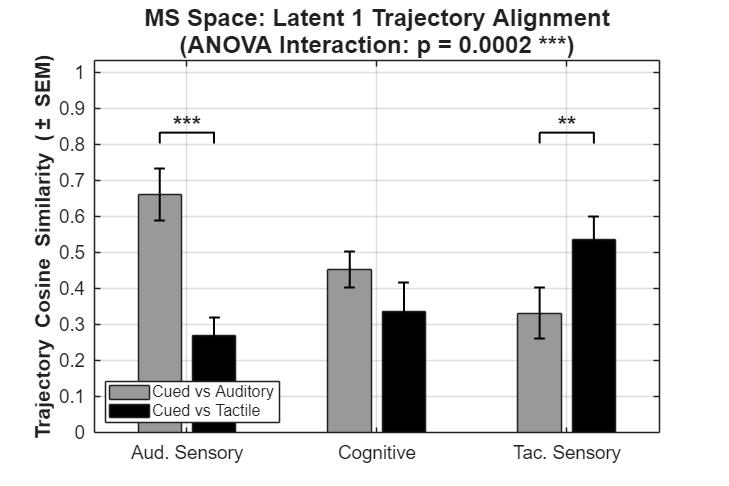

  ANOVA RESULTS FOR SPACE: MS (Latent 2)


                                SumSq      DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                               ________    __    ________    ______    __________    __________    __________    __________
    (Intercept)                  12.614     1      12.614    194.62    3.3657e-09    3.3657e-09    3.3657e-09    3.3657e-09
    Error                       0.84256    13    0.064812                                                                  
    (Intercept):Pair            0.61532     1     0.61532    19.341     0.0007205     0.0007205     0.0007205     0.0007205
    Error(Pair)                 0.41358 

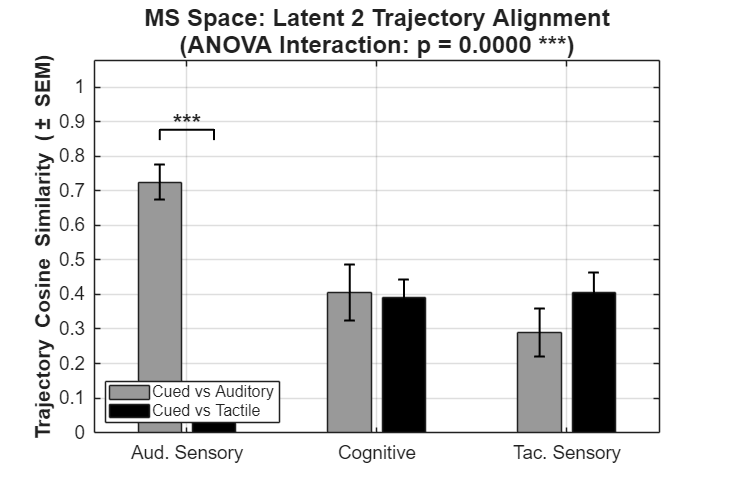

  ANOVA RESULTS FOR SPACE: MS (Latent 3)


                                SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                               _______    __    ________    ______    __________    __________    __________    __________
    (Intercept)                 14.788     1      14.788    111.83    9.3712e-08    9.3712e-08    9.3712e-08    9.3712e-08
    Error                       1.7191    13     0.13224                                                                  
    (Intercept):Pair           0.52759     1     0.52759    15.889     0.0015523     0.0015523     0.0015523     0.0015523
    Error(Pair)                0.43168    13 

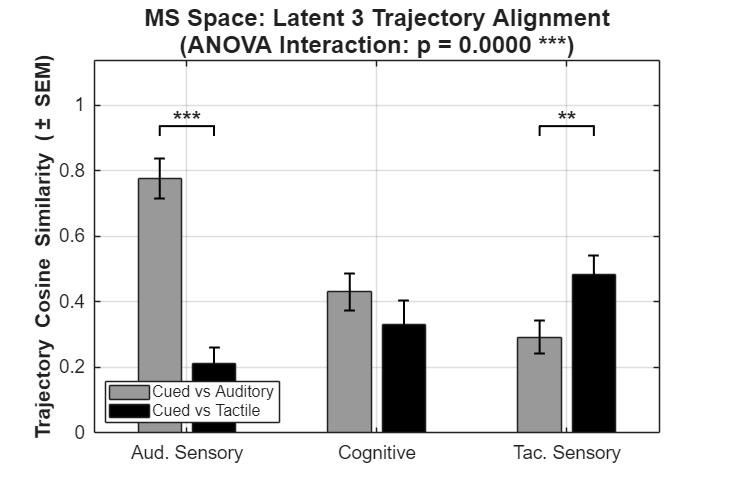

  ANOVA RESULTS FOR SPACE: MS (Latent 4)


                                SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                               _______    __    ________    ______    __________    __________    __________    __________
    (Intercept)                  12.44     1       12.44     205.8    2.3904e-09    2.3904e-09    2.3904e-09    2.3904e-09
    Error                      0.78585    13     0.06045                                                                  
    (Intercept):Pair           0.31229     1     0.31229    7.4466       0.01722       0.01722       0.01722       0.01722
    Error(Pair)                0.54519    13 

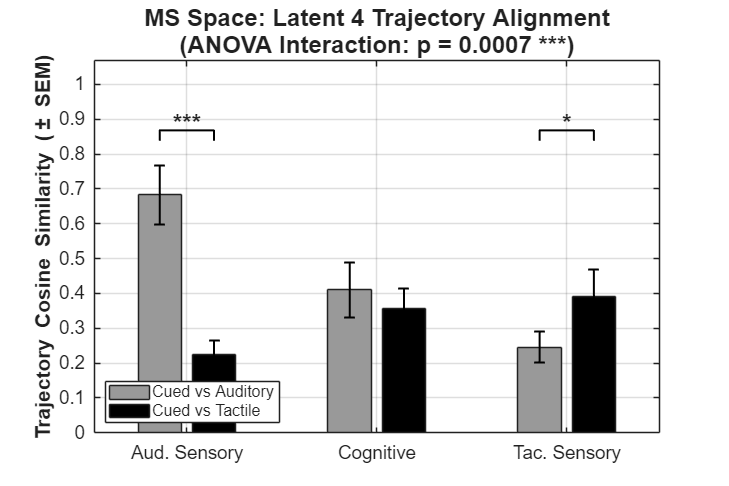

  ANOVA RESULTS FOR SPACE: Temp (Latent 1)


                                SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                               ________    __    ________    _______    __________    __________    __________    __________
    (Intercept)                  16.513     1      16.513     96.986    2.1482e-07    2.1482e-07    2.1482e-07    2.1482e-07
    Error                        2.2134    13     0.17027                                                                   
    (Intercept):Pair           0.019383     1    0.019383    0.43241       0.52228       0.52228       0.52228       0.52228
    Error(Pair)                 0.5

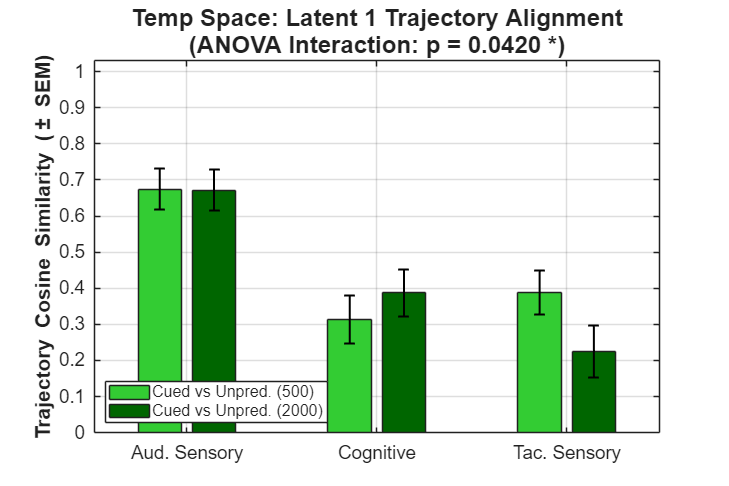

  ANOVA RESULTS FOR SPACE: Temp (Latent 2)


                                SumSq      DF     MeanSq         F          pValue       pValueGG      pValueHF      pValueLB 
                               ________    __    _________    ________    __________    __________    __________    __________
    (Intercept)                  15.059     1       15.059      114.55    8.1345e-08    8.1345e-08    8.1345e-08    8.1345e-08
    Error                        1.7089    13      0.13146                                                                    
    (Intercept):Pair           0.035495     1     0.035495      1.7121       0.21338       0.21338       0.21338       0.21338
    Error(Pair)            

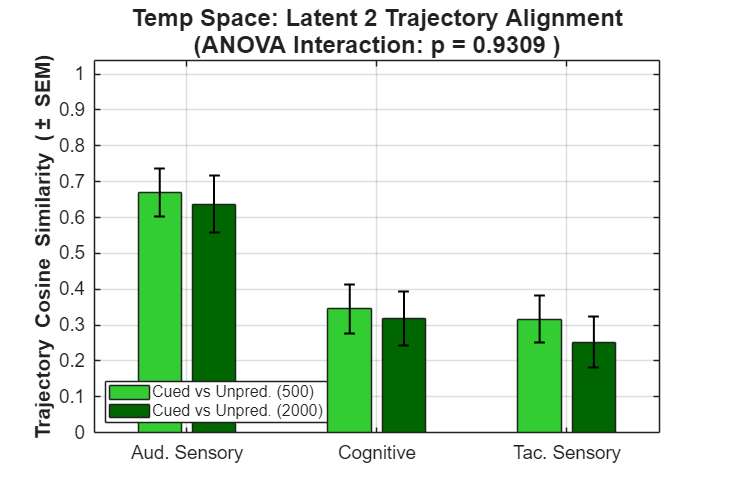

  ANOVA RESULTS FOR SPACE: Temp (Latent 3)


                                 SumSq       DF      MeanSq          F          pValue       pValueGG      pValueHF      pValueLB 
                               __________    __    __________    _________    __________    __________    __________    __________
    (Intercept)                    19.444     1        19.444       128.99    4.0316e-08    4.0316e-08    4.0316e-08    4.0316e-08
    Error                          1.9596    13       0.15074                                                                     
    (Intercept):Pair           0.00070981     1    0.00070981    0.0086459       0.92733       0.92733       0.92733       0.92733
    Error(Pair

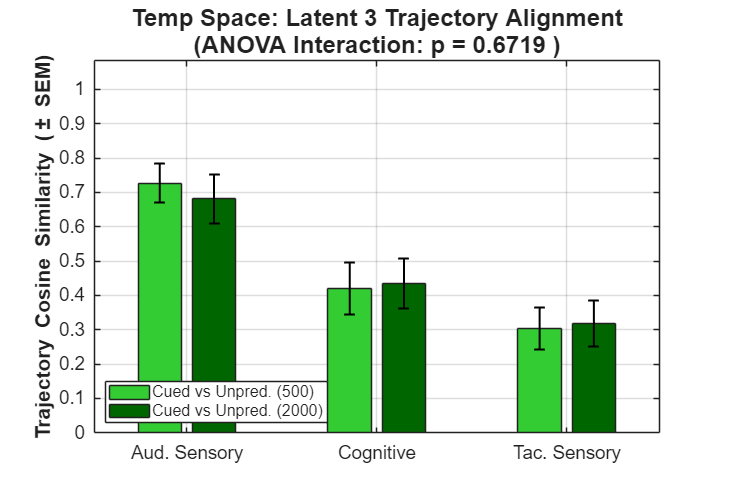

  ANOVA RESULTS FOR SPACE: Temp (Latent 4)


                                SumSq      DF     MeanSq         F          pValue       pValueGG      pValueHF      pValueLB 
                               ________    __    _________    ________    __________    __________    __________    __________
    (Intercept)                  17.645     1       17.645      134.35    3.1639e-08    3.1639e-08    3.1639e-08    3.1639e-08
    Error                        1.7074    13      0.13134                                                                    
    (Intercept):Pair           0.001834     1     0.001834    0.053478       0.82072       0.82072       0.82072       0.82072
    Error(Pair)            

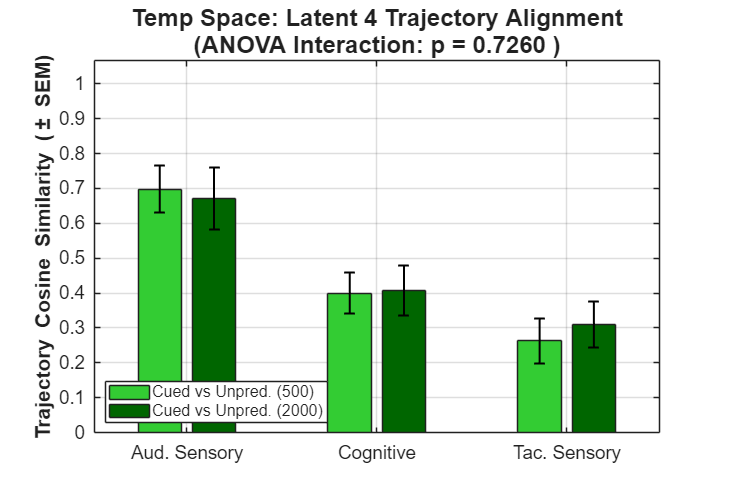

  ANOVA RESULTS FOR SPACE: Stim (Latent 1)


                                SumSq      DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                               ________    __    ________    ______    __________    __________    __________    __________
    (Intercept)                  17.061     1      17.061    106.63    1.2381e-07    1.2381e-07    1.2381e-07    1.2381e-07
    Error                          2.08    13        0.16                                                                  
    (Intercept):Pair           0.046024     1    0.046024    1.3116       0.27275       0.27275       0.27275       0.27275
    Error(Pair)                 0.45616 

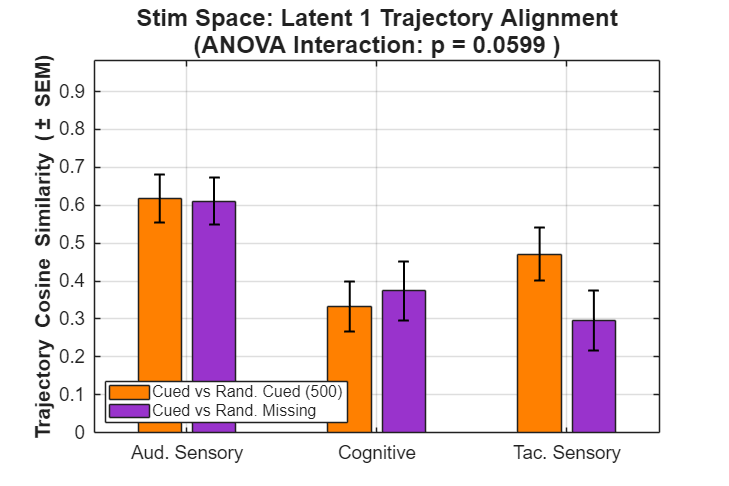

  ANOVA RESULTS FOR SPACE: Stim (Latent 2)


                                SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                               _______    __    ________    ______    __________    __________    __________    __________
    (Intercept)                 13.963     1      13.963    148.84    1.7135e-08    1.7135e-08    1.7135e-08    1.7135e-08
    Error                       1.2195    13    0.093811                                                                  
    (Intercept):Pair            0.2551     1      0.2551    11.094     0.0054181     0.0054181     0.0054181     0.0054181
    Error(Pair)                0.29894    13 

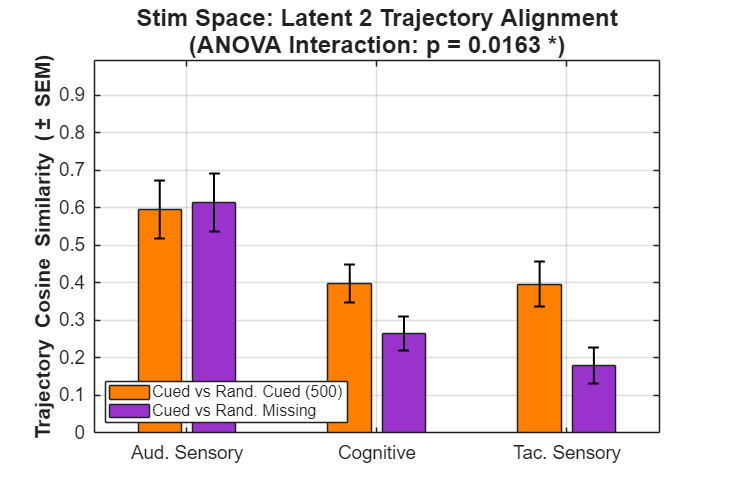

  ANOVA RESULTS FOR SPACE: Stim (Latent 3)


                                 SumSq      DF     MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                               _________    __    _________    _______    __________    __________    __________    __________
    (Intercept)                   19.576     1       19.576      233.7    1.0922e-09    1.0922e-09    1.0922e-09    1.0922e-09
    Error                         1.0889    13     0.083764                                                                   
    (Intercept):Pair           0.0039132     1    0.0039132    0.14663       0.70797       0.70797       0.70797       0.70797
    Error(Pair)            

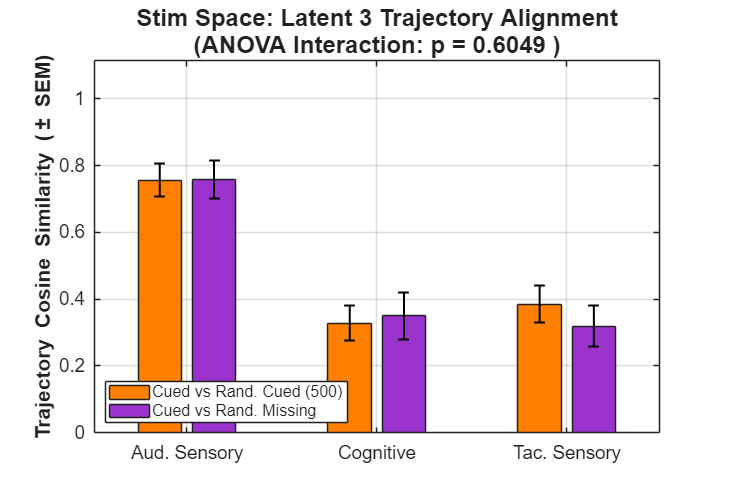

  ANOVA RESULTS FOR SPACE: Stim (Latent 4)


                                 SumSq      DF     MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                               _________    __    _________    _______    __________    __________    __________    __________
    (Intercept)                   16.297     1       16.297     110.89    9.8434e-08    9.8434e-08    9.8434e-08    9.8434e-08
    Error                         1.9105    13      0.14696                                                                   
    (Intercept):Pair            0.091805     1     0.091805     3.1569      0.098999      0.098999      0.098999      0.098999
    Error(Pair)            

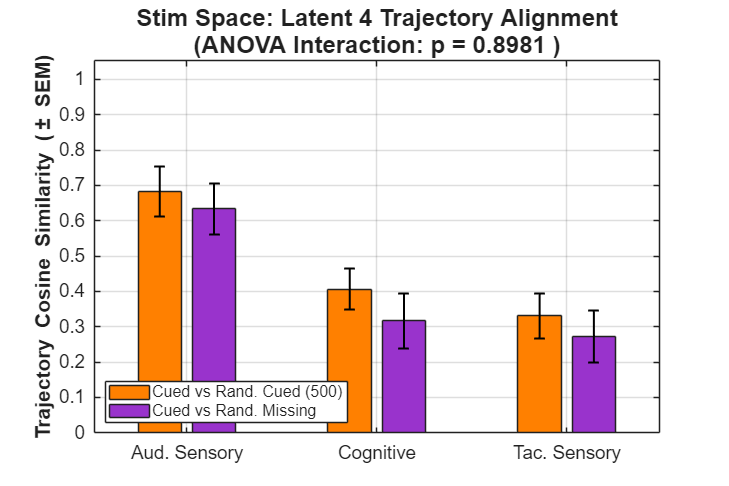

warning('off', 'all');

win_bounds = [0.50 0.85; 0.85 1.00; 1.00 1.35];
win_labels = {'Aud. Sensory', 'Cognitive', 'Tac. Sensory'};
num_windows = size(win_bounds, 1);

% --- NEW: Define how many latents to process ---
num_latents_to_plot = 4; 

for g = 1:length(group_names)
    group = group_names{g};
    target_conds = compare_groups.(group);
    
    base_idx = find(strcmp(target_conds, 'P1'));
    if isempty(base_idx), base_idx = 1; end
    
    comp_indices = setdiff(1:length(target_conds), base_idx);
    num_pairs = length(comp_indices);
    
    % --- NEW: Loop through Latents 1 to 4 ---
    for lat = 1:num_latents_to_plot
        
        fprintf('\n======================================================\n');
        fprintf('  ANOVA RESULTS FOR SPACE: %s (Latent %d)\n', group, lat);
        fprintf('======================================================\n');
        
        anova_data = nan(num_subjs, num_pairs * num_windows); 
        varNames = cell(1, num_pairs * num_windows);
        pair_factors = cell(num_pairs * num_windows, 1); 
        win_factors = cell(num_pairs * num_windows, 1);
        
        col_idx = 1;
        for p = 1:num_pairs
            c_target = comp_indices(p);
            
            for w = 1:num_windows
                t_start = win_bounds(w, 1); t_end = win_bounds(w, 2);
                idx_win = find(time_ms_eeg >= t_start & time_ms_eeg <= t_end);
                
                for s = 1:num_subjs
                    % --- UPDATED: Extract 1D trajectories using 'lat' ---
                    x = squeeze(Z_loso.(group)(s, idx_win, lat, base_idx));
                    y = squeeze(Z_loso.(group)(s, idx_win, lat, c_target));
                    
                    valid = ~isnan(x) & ~isnan(y);
                    if sum(valid) > 1
                        x_v = x(valid); y_v = y(valid);
                        anova_data(s, col_idx) = abs(dot(x_v, y_v) / (norm(x_v) * norm(y_v)));
                    end
                end
                
                varNames{col_idx} = matlab.lang.makeValidName(sprintf('P%d_W%d', p, w));
                pair_factors{col_idx} = sprintf('%s vs %s', friendly_names(target_conds{base_idx}), friendly_names(target_conds{c_target}));
                win_factors{col_idx} = win_labels{w};
                col_idx = col_idx + 1;
            end
        end
        
        % Clean NaNs to prevent RM ANOVA failure
        valid_cols = ~any(isnan(anova_data), 1);
        anova_data_bal = anova_data(:, valid_cols);
        
        if size(anova_data_bal, 2) > 1
            tbl = array2table(anova_data_bal, 'VariableNames', varNames(valid_cols));
            Pair = categorical(pair_factors(valid_cols)); Window = categorical(win_factors(valid_cols));
            withinTbl = table(Pair, Window);
            model_spec = sprintf('%s-%s ~ 1', varNames{find(valid_cols, 1, 'first')}, varNames{find(valid_cols, 1, 'last')});
            
            try
                rm = fitrm(tbl, model_spec, 'WithinDesign', withinTbl);
                ranovatbl = ranova(rm, 'WithinModel', 'Pair*Window'); 
                disp(ranovatbl);
                
                int_idx = strcmp(ranovatbl.Properties.RowNames, '(Intercept):Pair:Window');
                pval_int = ranovatbl.pValue(int_idx);
            catch
                pval_int = NaN;
            end
        else
            pval_int = NaN;
        end
        
        % --- CREATE BAR CHART FIGURE ---
        % Staggered figure positions so windows don't overlap completely
        fig_x_pos = 100 + (g * 30);
        fig_y_pos = 100 + (lat * 30);
        figure('Position', [fig_x_pos, fig_y_pos, 900, 600], 'Name', sprintf('ANOVA: %s Traj Sim (Latent %d)', group, lat));
        
        plot_means = zeros(num_windows, num_pairs); 
        plot_sems  = zeros(num_windows, num_pairs); 
        legend_names = cell(1, num_pairs);
        
        for p = 1:num_pairs
            for w = 1:num_windows
                col = (p-1)*num_windows + w;
                plot_means(w, p) = mean(anova_data(:, col), 'omitnan');
                plot_sems(w, p)  = std(anova_data(:, col), 'omitnan') / sqrt(num_subjs);
            end
            c_target = comp_indices(p);
            legend_names{p} = sprintf('%s vs %s', friendly_names(target_conds{base_idx}), friendly_names(target_conds{c_target}));
        end
        
        b = bar(plot_means, 'grouped'); hold on;
        for p = 1:num_pairs
            c_target = target_conds{comp_indices(p)};
            if isfield(color_map, c_target), b(p).FaceColor = color_map.(c_target); else, b(p).FaceColor = [0.5 0.5 0.5]; end
            errorbar(b(p).XEndPoints, plot_means(:, p), plot_sems(:, p), 'k', 'linestyle', 'none', 'LineWidth', 1.5, 'CapSize', 8);
        end
        
        % --- POST-HOC TESTS & SIGNIFICANCE BRACKETS ---
        max_y_val = max(plot_means + plot_sems, [], 'all'); 
        for w = 1:num_windows
            if num_pairs < 2, continue; end
            
            col_1 = (1-1)*num_windows + w; 
            col_2 = (2-1)*num_windows + w;
            
            % Ad-hoc hypothesis testing
            if contains(win_labels{w}, 'Aud') || contains(win_labels{w}, 'Tac1') 
                [~, p_posthoc] = ttest(anova_data(:, col_1), anova_data(:, col_2), 'Tail', 'right');
            elseif contains(win_labels{w}, 'Tac') && ~contains(win_labels{w}, 'Tac1')
                [~, p_posthoc] = ttest(anova_data(:, col_1), anova_data(:, col_2), 'Tail', 'left');
            else
                [~, p_posthoc] = ttest(anova_data(:, col_1), anova_data(:, col_2), 'Tail', 'both');
            end
            
            if p_posthoc < 0.05
                x1 = b(1).XEndPoints(w);
                x2 = b(2).XEndPoints(w);
                y_h = max_y_val + 0.1; 
                plot([x1, x1, x2, x2], [y_h-0.03, y_h, y_h, y_h-0.03], '-k', 'LineWidth', 1.5);
                
                star_str = '*'; if p_posthoc < 0.01, star_str = '**'; end; if p_posthoc < 0.001, star_str = '***'; end
                text(mean([x1, x2]), y_h + 0.02, star_str, 'HorizontalAlignment', 'center', 'FontSize', 18, 'FontWeight', 'bold');
            end
        end
        hold off;

        set(gca, 'XTick', 1:num_windows, 'XTickLabel', win_labels, 'FontSize', 14);
        ylim([0, max_y_val + 0.3]); 
        ylabel('Trajectory Cosine Similarity (\pm SEM)', 'FontSize', 16, 'FontWeight', 'bold');
        
        % --- UPDATED: Dynamic Title using 'lat' ---
        title_str = sprintf('%s Space: Latent %d Trajectory Alignment', group, lat);
        if ~isnan(pval_int)
            star_str = ''; if pval_int < 0.05, star_str = '*'; end; if pval_int < 0.01, star_str = '**'; end; if pval_int < 0.001, star_str = '***'; end
            title_str = {title_str, sprintf('(ANOVA Interaction: p = %.4f %s)', pval_int, star_str)};
        end
        title(title_str, 'FontSize', 18, 'FontWeight', 'bold'); 
        grid on; legend(b, legend_names, 'Location', 'southwest', 'FontSize', 12);
    end
end

warning('on', 'all');
disp('RM ANOVA & Plotting completed successfully.');

RM ANOVA & Plotting completed successfully.
